# 8주차 — 주파수응답: 사인을 넣어 보면

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

**1. 올해(2026) 수업 — 항상 이 두 곳에 올라옵니다**

수업이 끝나면 그날 녹화가 재생목록에 올라가고, 자료를 고치면 GitHub 이 곧바로 갱신됩니다. **빠진 수업이 있거나 따라가지 못한 곳이 있으면 이 둘을 먼저 보십시오.** 강의노트 · 실습 스크립트 · Simulink 모델 · 숙제가 모두 GitHub 에 있습니다.

**2. 담당교수가 직접 한 강의 다섯 과목**

기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**3. MATLAB 이나 Simulink 가 아직 익숙하지 않다면**

실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

지난 주까지는 **시간**으로 봤습니다. 계단을 넣고 얼마나 빨리, 얼마나 흔들리며 따라오는지를 봤습니다.

오늘부터는 **주파수**로 봅니다. 사인을 넣고 크기와 위상이 어떻게 달라지는지 봅니다.

왜 굳이 다른 눈으로 보는가 — 세 가지 이유가 있습니다.

- **모델이 없어도 잴 수 있다.** 사인파를 넣어 보면 되니까 실험만으로 얻는다

- **곱셈이 덧셈이 된다.** 여러 블록이 이어진 시스템을 손으로 그릴 수 있다

- **여유를 숫자로 준다.** 모델이 조금 틀려도 버티는지를 9주차에서 본다

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W08_Bode` 폴더 안에 있습니다.

오늘 처음 쓰는 도우미 함수 두 개도 `common/` 에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**선형 시불변 시스템에 사인을 넣으면 같은 주파수의 사인이 나온다. 달라지는 것은 크기와 위상뿐이고, 그 둘을 주파수마다 모은 것이 보드 선도다.**

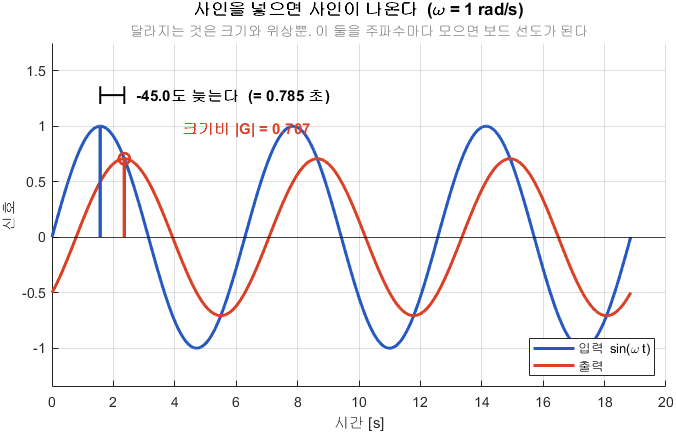

사인을 넣으면 크기와 위상만 달라진 사인이 나온다

**그림 파일** `w08_sine_io.png` — `common/dg_sine_io.m` 의 `dg_sine_io` · 다시 만들려면 `make_figures('w08_sine_io')`

**만드는 곳** — `common/dg_sine_io.m` (`make_figures('w08_sine_io')`). 명령창에서 `dg_sine_io(3)` 처럼 다른 주파수로 직접 불러도 됩니다 **직접 바꿔 보려면** — `W08_01_sine_to_bode.m` 의 **1절**에서 `w` 를 $0.1$, $1$, $10$ 으로 바꿔 실행

그림 해석 — **이 표를 그대로 읽으면 오늘 0절 설명이 됩니다**

$|G| = 0.707$ 과 위상 $-45^\circ$ — 이 **두 숫자**가 주파수 $\omega=1$ 에서 이 시스템을 완전히 설명합니다. 주파수를 바꿔 가며 이 두 숫자를 모으면 그것이 보드 선도입니다.

오늘의 계단

- **0-1 ~ 0-2절** 가장 작은 예 하나로 크기·위상·진폭 $A$ 를 확인

- **1~2절** 사인을 넣으면 무슨 일이 생기는가 (단위 Hz 와 rad/s, RC 회로 예제)

- **3절** 크기와 위상을 어떻게 재는가 + **보드 선도의 정의**

- **4절** 왜 dB 이고 왜 로그축인가

- **5절** 손으로 그리는 법 (네 조각과 점근선), 그리고 **이득 **$K$** 를 바꾸면**

- **6절** 2차 항의 봉우리

- **7절** 필터 — 주파수로 신호를 골라내기

- **8절** Simulink 로 직접 재 보기

## 0-1. 가장 작은 예부터

파라미터가 하나뿐인 시스템으로 시작합니다.


$$G(s) = \frac{1}{s+1}$$


여기에 $\omega = 1$ 인 사인을 넣으면 어떻게 되는지 봅니다. 손으로 계산할 수 있습니다. $s$ 자리에 $j\omega = j$ 를 넣기만 하면 됩니다.


$$G(j1) = \frac{1}{j+1}$$


크기는 분모의 크기로 나누면 되고


$$|G(j1)| = \frac{1}{|1+j|} = \frac{1}{\sqrt{2}} \approx 0.707$$


위상은 분모의 각을 빼면 됩니다.


$$\angle G(j1) = -\angle(1+j) = -45^\circ$$


즉 **크기는 0.707 배로 줄고, 45도 늦게 따라온다** 는 뜻입니다. 정말 그런지 코드로 확인합니다.

G0 = 1/(s+1);
w0 = 1;
G0jw = freqresp(G0, w0);
mag_hand = 1/sqrt(2)                 % 손계산한 크기
mag_matlab = abs(G0jw)               % MATLAB 이 구한 크기
phase_matlab = rad2deg(angle(G0jw))  % 위상 [도]
t = (0:0.02:20)';
u = sin(w0*t);
y = lsim(G0, u, t);
plot(t, u, 'LineWidth', 2); hold on;
plot(t, y, 'LineWidth', 2); grid on;
xlabel('시간 [s]'); ylabel('신호');
legend('입력 sin(t)', '출력', 'Location','southeast');
title('0.707 배로 줄고 45도 늦는다');

## 0-1-1. 진폭이 $1$ 이 아니면 — $A$ 는 어디로 가는가

바로 앞 절에서는 진폭이 $1$ 인 사인 $\sin \omega t$ 를 넣었습니다. 그런데 실제로 신호를 넣을 때 진폭이 꼭 $1$ 일 리는 없습니다. 전압이면 $5$ V 일 수도 있고 $0.1$ V 일 수도 있습니다. **그러면 결과가 달라질까요?**

**비유** — 확성기의 볼륨 손잡이입니다. 손잡이를 두 배로 돌리면 소리가 두 배로 커질 뿐, 노래의 **음정(주파수)** 도 **박자(위상)** 도 그대로입니다.

왜 그런지는 선형 시스템의 성질 하나로 끝납니다.

- 선형 시스템은 **입력을 **$A$** 배 하면 출력도 정확히 **$A$** 배**가 됩니다 (제차성)

- 앞 절에서 $\sin \omega t$ 를 넣었더니 $|G(j\omega)| \sin(\omega t + \angle G(j\omega))$ 가 나왔습니다

- 그러므로 $A \sin \omega t$ 를 넣으면 그 전체에 $A$ 만 곱해집니다

정리하면 이렇습니다. **이것이 교수자 강의자료 2쪽의 그림입니다.**


$$u(t) = A \sin \omega t \quad \Longrightarrow \quad y(t) = A\,|G(j\omega)|\,\sin\!\left(\omega t + \angle G(j\omega)\right)$$


기호마다 뜻을 붙이면

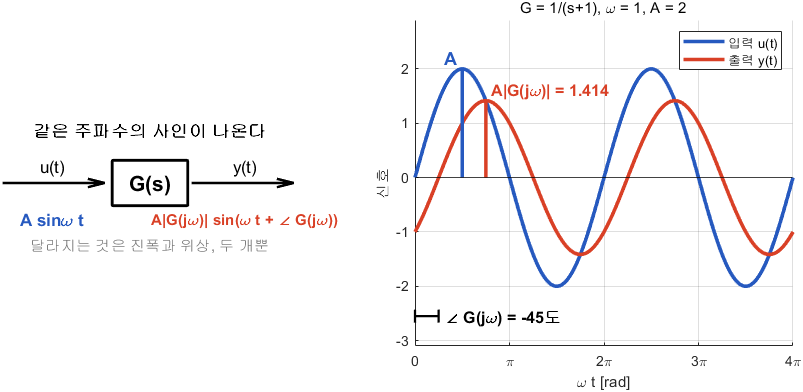

입력 진폭 A 가 출력에서 A 곱하기 크기로 바뀐다

**그림 파일** `w08_sine_io_block.png` — `make_figures.m` 의 `fig_w08_sine_io_block` · 다시 만들려면 `make_figures('w08_sine_io_block')`

**만드는 곳** — `make_figures.m` 의 `fig_w08_sine_io_block` **직접 확인해 보려면** — `W08_04_slide_examples.m` 의 **1절**

그림 해석

**가장 중요한 결론 — 보드 선도에 **$A$** 는 등장하지 않습니다.**

- 출력 진폭은 $A \times |G(j\omega)|$ 이므로, **진폭의 비**를 만들면 $\frac{\text{출력 진폭}}{\text{입력 진폭}} = |G(j\omega)|$ 가 되어 $A$ 가 약분됩니다

- 위상차도 $A$ 와 아무 상관이 없습니다

- 그래서 주파수응답은 $A$ 를 얼마로 두고 재도 **같은 답**이 나옵니다. 실습에서 `Amplitude` 를 그냥 $1$ 로 두는 이유가 이것입니다

손으로 한 번 확인해 봅니다. $G = \frac{1}{s+1}$, $\omega = 1$, $A = 2$ 이면


$$G(j1) = \frac{1}{1+j} = \frac{1-j}{2}, \qquad |G(j1)| = \frac{\sqrt{2}}{2} = 0.7071, \qquad \angle G(j1) = -45^\circ$$


이므로 출력 진폭은 $2 \times 0.7071 = 1.4142$ 여야 합니다. 코드로 재 봅니다.

A_in = 2;                                  % 입력 진폭을 1 이 아닌 값으로
G_a  = 1/(s + 1);
w_a  = 1;

Gj_a      = freqresp(G_a, w_a);            % 복소수 G(jw)
amp_out   = A_in * abs(Gj_a)               % 예상 출력 진폭 = A * |G|
phase_deg = rad2deg(angle(Gj_a))           % 위상 [도]

t_a = (0:0.001:30)';                       % 정상상태까지 충분히 길게
u_a = A_in * sin(w_a*t_a);
y_a = lsim(G_a, u_a, t_a);
amp_measured = max(y_a(end-6000:end))      % 뒤쪽 구간에서 실제로 잰 진폭

## 0-2. 45도가 얼마나 늦는 것인가

위상은 각도지만 실제로는 **시간지연**입니다. 바꾸는 법은 간단합니다.


$$\text{시간지연} = \frac{\text{위상}[\mathrm{rad}]}{\omega}$$


위 예에서 $45^\circ = \pi/4$ 라디안이고 $\omega = 1$ 이므로 $\pi/4 \approx 0.785$ 초 늦습니다.

**주의할 점** — 같은 위상이라도 주파수가 다르면 시간지연이 다릅니다. 주파수가 두 배면 같은 각도라도 지연은 절반입니다.

w = [0.5 1 2 10]';          % 주파수 [rad/s]
delay = (pi/4)./w;          % 45 도가 뜻하는 시간 지연 [s]
table(w, delay)

## 1. 왜 사인인가

계단이나 임펄스가 아니라 왜 하필 사인인가.

이유는 하나입니다. **선형 시불변 시스템에서 사인만이 모양을 유지합니다.**

- 계단을 넣으면 출력은 계단이 아니다 (지수함수가 섞인 곡선이 나온다)

- 임펄스를 넣으면 출력은 임펄스가 아니다

- **사인을 넣으면 출력도 사인이다.** 크기와 위상만 달라진다

모양이 유지되므로 "무엇이 달라졌는가" 를 숫자 **두 개**로 요약할 수 있습니다. 그 두 숫자가 크기비와 위상차입니다.

그리고 푸리에가 알려 준 대로 어떤 신호든 사인의 합으로 쓸 수 있으므로, 사인 하나에 대한 답을 알면 **모든 신호에 대한 답을 아는 것**입니다.

## 2. 정말 사인이 나오는가 — 유도

말로만 하지 말고 식으로 확인합니다.

입력이 $u(t) = \sin(\omega t)$ 이면 라플라스 변환은


$$U(s) = \frac{\omega}{s^2 + \omega^2} = \frac{\omega}{(s-j\omega)(s+j\omega)}$$


출력은 $Y(s) = G(s)U(s)$ 이므로 부분분수로 쪼개면 이렇게 됩니다.


$$Y(s) = \frac{A}{s - j\omega} + \frac{\bar{A}}{s + j\omega} + (\text{G 의 극점에서 오는 항들})$$


오른쪽 괄호의 항들은 $G$ 의 극점이 좌반면에 있으면 **시간이 지나면 사라집니다.** 남는 것은 앞의 두 항뿐이고, 이것이 정상상태 응답입니다.

계수 $A$ 를 구하면


$$A = \left. (s - j\omega)\,\frac{G(s)\,\omega}{(s-j\omega)(s+j\omega)} \right|_{s = j\omega} = \frac{G(j\omega)}{2j}$$


이것을 되돌리면 결국


$$y_{ss}(t) = |G(j\omega)|\,\sin\left(\omega t + \angle G(j\omega)\right)$$


**결론** — 정상상태 사인응답의 크기비와 위상차는 그냥 $G(s)$ 에 $s = j\omega$ 를 넣은 값입니다. 외울 것도 없습니다.

## 2-1. 앞 주차와 이어 보기

같은 이야기가 계속 반복되고 있습니다.

- **계단**의 정상상태 $\rightarrow$ $G(0)$ 을 본다 (5주차 `dcgain`)

- **사인**의 정상상태 $\rightarrow$ $G(j\omega)$ 를 본다 (오늘)

둘 다 "입력의 극점 자리에 $s$ 를 넣는다" 는 같은 규칙입니다. 계단의 극점은 $s = 0$, 사인의 극점은 $s = \pm j\omega$ 이기 때문입니다.

## 2-2. 주파수의 단위 — Hz 와 rad/s 를 섞지 말 것

지금까지 $\omega$ 라고만 써 왔습니다. 그런데 실험실에서 신호발생기를 돌리거나 Simulink 의 사인 블록을 쓸 때는 **Hz** 라는 단위를 보게 됩니다. 이 둘을 섞으면 그림이 $2\pi \approx 6.28$ 배만큼 어긋납니다. **이 과목에서 가장 흔한 단위 실수**이므로 여기서 한 번에 정리합니다.

**비유** — 같은 회전을 두 가지로 셀 수 있습니다. "1 초에 세 바퀴" 라고 세면 Hz 이고, "1 초에 몇 라디안" 이라고 세면 rad/s 입니다. 한 바퀴가 $2\pi$ 라디안이므로 둘 사이에는 $2\pi$ 라는 환산계수가 있습니다.

셋을 한 줄로 정의합니다.

- $T$ — **주기**. 사인이 한 번 완전히 반복되는 데 걸리는 시간 [s]

- $f$ — **주파수**. 1 초에 몇 번 반복되는가 [Hz]. 정의상 $f = 1/T$

- $\omega$ — **각주파수**. 1 초에 몇 라디안을 도는가 [rad/s]

한 번 반복하는 동안 각도는 $2\pi$ 라디안 늘어납니다. 그것이 $T$ 초 동안 일어나므로, 1 초에 늘어나는 각도는 $2\pi / T$ 입니다. 그러므로


$$f = \frac{1}{T} = \frac{\omega}{2\pi}, \qquad \omega = 2\pi f = \frac{2\pi}{T}$$


그래서 사인 신호를 적는 두 방법은 **완전히 같은 식**입니다.


$$u(t) = A \sin \omega t = A \sin 2\pi f t$$


숫자로 감을 잡아 둡니다.

**Simulink 에서 틀리기 쉬운 자리 — Sine Wave 블록**

- `Sine Wave` 블록의 `Frequency` 칸은 **rad/s** 를 받습니다. Hz 가 아닙니다

- 그러므로 $1$ Hz 짜리 사인을 넣고 싶으면 그 칸에 `1` 이 아니라 `2*pi*1` 이라고 적어야 합니다. **이 한 줄이 이 블록에서 가장 많이 틀리는 자리입니다**

- `1` 이라고 적으면 $\omega = 1$ rad/s, 곧 $f = 0.159$ Hz 인 신호가 나갑니다. 의도한 것보다 $6.28$ 배 느린 신호입니다

- 그래도 헷갈리면 `Amplitude`, `Frequency`, `Phase`, `Sample time` 네 칸 중 `Frequency` 칸에만 `2*pi*` 를 붙인다고 외우면 됩니다

환산을 코드로 확인합니다.

f_hz  = [0.1; 1; 3; 60];        % 주파수 [Hz]
T_sec = 1 ./ f_hz;              % 주기 [s]
w_rad = 2*pi*f_hz;              % 각주파수 [rad/s]
table(f_hz, T_sec, w_rad)

## 2-3. 강의자료 3쪽 예제 — RC 회로에 $1$ Hz 와 $3$ Hz 를 넣어 본다

앞 절까지는 $G = 1/(s+1)$ 이라는 **만들어 낸** 시스템이었습니다. 이제 **실제 부품 두 개로 만들 수 있는 회로**에 사인을 넣어 보겠습니다. 교수자 강의자료 3쪽의 예제를 그대로 가져온 것입니다.

회로는 2주차에서 본 RC 저역통과 회로입니다 — 저항 $R$ 하나와 축전기 $C$ 하나를 직렬로 잇고, **축전기 양단 전압**을 출력으로 봅니다.

전달함수를 세 걸음으로 유도합니다.

- **1단계** 전류는 하나뿐입니다. 라플라스 영역에서 저항의 임피던스는 $R$, 축전기의 임피던스는 $\frac{1}{Cs}$ 입니다

- **2단계** 두 임피던스가 직렬이므로 출력 전압은 **분압**으로 결정됩니다


$$\frac{Y(s)}{U(s)} = \frac{\frac{1}{Cs}}{R + \frac{1}{Cs}}$$


- **3단계** 분자와 분모에 $Cs$ 를 곱해 분수 안의 분수를 없앱니다


$$G(s) = \frac{Y(s)}{U(s)} = \frac{1}{RCs + 1}$$


$RC$ 라는 곱이 하나의 숫자로 묶였습니다. 이것이 **시정수** $\tau = RC$ 입니다. 강의자료의 값을 넣으면


$$R = 100\ \Omega, \quad C = 0.001\ \mathrm{F} \quad \Rightarrow \quad \tau = RC = 0.1\ \mathrm{s} \quad \Rightarrow \quad G(s) = \frac{1}{0.1s + 1}$$


**이제 **$1$** Hz 사인을 넣으면 출력이 어떻게 될지 손으로 계산합니다.**

- **1단계** Hz 를 rad/s 로 바꿉니다 — $\omega = 2\pi f = 2\pi \times 1 = 6.283$ rad/s

- **2단계** $s$ 자리에 $j\omega$ 를 넣습니다


$$G(j\omega) = \frac{1}{0.1\,j\omega + 1} = \frac{1}{1 + j(0.1 \times 6.283)} = \frac{1}{1 + j0.6283}$$


- **3단계** 분수의 크기는 "분자 크기 나누기 분모 크기" 입니다. 분자는 $1$, 분모는 $\sqrt{1^2 + 0.6283^2} = \sqrt{1.3948} = 1.1810$ 이므로


$$|G(j\omega)| = \frac{1}{1.1810} = 0.847$$


- **4단계** 분수의 위상은 "분자 위상 빼기 분모 위상" 입니다. 분자의 위상은 $0$, 분모의 위상은 $\tan^{-1}(0.6283/1) = 32.1^\circ$ 이므로


$$\angle G(j\omega) = 0^\circ - 32.1^\circ = -32^\circ$$


$3$ Hz 에 대해서도 똑같이 하면 $\omega = 6\pi = 18.85$, $0.1\omega = 1.885$, 크기는 $1/\sqrt{1+1.885^2} = 1/2.134 = 0.469$, 위상은 $-\tan^{-1}(1.885) = -62^\circ$ 입니다.

**즉 같은 회로인데 넣는 주파수에 따라 답이 다릅니다.** 바로 이것이 "주파수응답" 이라는 말의 뜻입니다.

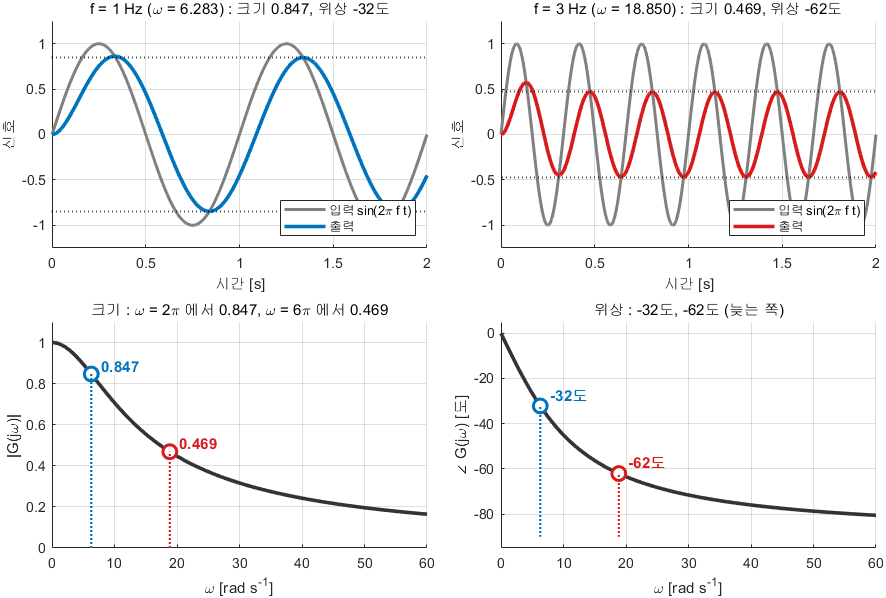

RC 회로에 1 Hz 와 3 Hz 를 넣은 결과 (강의자료 3쪽)

**그림 파일** `w08_rc_sine.png` — `make_figures.m` 의 `fig_w08_rc_sine` · 다시 만들려면 `make_figures('w08_rc_sine')`

**만드는 곳** — `make_figures.m` 의 `fig_w08_rc_sine` **직접 확인해 보려면** — `W08_04_slide_examples.m` 의 **2절**

그림 해석

**Simulink 로 같은 것을 확인하려면**

교수자 강의자료의 모델 이름은 `Ch6_Bode_plot_Sine_wave.slx` 입니다. 블록 네 종류만 있으면 똑같이 만들 수 있습니다.

이 과목에서는 같은 일을 `W08_SineSweep.slx` 가 합니다. 주파수를 하나씩 바꿔 가며 자동으로 훑기 때문에 그림 한 장이 바로 나옵니다 (8절에서 다룹니다).

손계산을 코드로 검산합니다.

R_rc   = 100;                       % 저항 [옴]
C_rc   = 0.001;                     % 축전기 [F]
tau_rc = R_rc * C_rc                % 시정수 = RC [s]
G_rc   = 1/(tau_rc*s + 1);

f_rc   = [1; 3];                    % [Hz]
w_rc   = 2*pi*f_rc;                 % [rad/s]
Gj_rc  = squeeze(freqresp(G_rc, w_rc));

mag_hand = 1 ./ sqrt(1 + (tau_rc*w_rc).^2);          % 손으로 유도한 크기
ph_hand  = -atan(tau_rc*w_rc) * 180/pi;              % 손으로 유도한 위상 [도]
mag_mat  = abs(Gj_rc);                               % MATLAB 이 준 크기
ph_mat   = angle(Gj_rc) * 180/pi;                    % MATLAB 이 준 위상 [도]

table(f_rc, w_rc, mag_hand, mag_mat, ph_hand, ph_mat)

## 2-4. 그 모델을 실제로 만들어 두었습니다 — `W08_RC_SineCompare.slx`

왜 필요한가 — 앞 절에서 블록 네 종류의 표만 보았습니다. 표만 보면 "그래서 돌리면 정말 $0.847$ 과 $0.469$ 가 나오는가" 를 확인할 수 없습니다. 그래서 강의자료 $3$쪽의 모델을 이 폴더에 **그대로 만들어 두었습니다.**

모델의 구조는 두 줄입니다. 같은 회로를 두 벌 두고 **주파수만 다르게** 넣습니다.

두 줄의 `Transfer Fcn` 이 완전히 같다는 것이 이 모델의 핵심입니다. **회로는 하나도 안 바꾸고 넣는 주파수만 바꿉니다.** 그런데도 답이 다릅니다. 그것이 주파수응답입니다.

측정을 코드로 하기 위해 네 개의 `To Workspace` 블록 (`u1`, `y1`, `u3`, `y3`) 을 달아 두었습니다. `Mux` 와 `To Workspace` 는 $1$주차에서 설명했고, `Sine Wave` 의 파라미터 전체는 아래 $8$절에 정리해 두었습니다.

**반드시 기억할 것 하나** — `Sine Wave` 블록의 `Frequency` 칸은 **Hz 가 아니라 rad/s** 입니다.


$$\omega = 2\pi f$$


이므로 $1$ Hz 는 `2*pi` $= 6.283$, $3$ Hz 는 `6*pi` $= 18.850$ 을 넣습니다. $1$ 과 $3$ 을 그냥 넣으면 $0.159$ Hz 와 $0.477$ Hz 를 넣은 것이 되어 크기가 $0.998$ 과 $0.983$ 으로 나옵니다. 거의 $1$ 이라 **틀린 줄도 모릅니다.** 이 실수가 가장 흔합니다.

돌리는 법과 재는 법

- 모델을 만들거나 되살리려면 — `W08_build_rc_model.m` 을 실행합니다

- 돌리고 재려면 — `W08_05_rc_simulink.m` 을 실행합니다

그 스크립트가 파형에서 숫자를 꺼내는 방법은 두 줄입니다.


$$\text{크기비} = \frac{(\max y - \min y)/2}{(\max u - \min u)/2}, \qquad \text{위상차} = -\omega\,(t_y - t_u)$$


여기서 $t_u$, $t_y$ 는 각 신호가 **올라가며 **$0$** 을 지나는 시각**입니다. 뒤 식의 유도는 한 줄입니다 — 출력이 $\sin(\omega t + \phi)$ 꼴이라면 올라가며 $0$ 이 되는 시각은 $\omega t_y + \phi = 0$, 즉 $\phi = -\omega t_y$ 입니다. 입력의 영점통과 시각 $t_u$ 를 기준으로 빼면 위 식이 됩니다. **늦으면** ($t_y > t_u$) 위상이 음수가 됩니다.

**반드시 정상상태 구간만 씁니다.** 처음 몇 주기에는 과도응답이 섞여 있어 진폭이 아직 자리를 못 잡았습니다. $\tau = 0.1$ 초이므로 $0.5$ 초면 $5\tau$ 가 지나 과도항이 $e^{-5} = 0.7\%$ 로 사라집니다. 그래서 스크립트는 $t \ge 0.5$ 초만 잘라 씁니다.

실제로 돌려 본 결과입니다.

네 열이 전부 같습니다. 크기는 $5.5 \times 10^{-5}$, 위상은 $0.04^\circ$ 안에서 맞습니다. 남은 차이는 **파형에서 눈금을 읽는 오차**이지 이론의 차이가 아닙니다.

왜 중요한가 — 이 절에서 **손계산과 시뮬레이션과 bode 명령이 같은 것을 계산한다**는 것이 확인되었습니다. 그러므로 다음 절부터는 셋 중 가장 빠른 `bode` 만 쓰면 됩니다. 믿을 근거를 여기서 만들어 둔 것입니다.

## 3. 크기와 위상을 어떻게 재는가

실험으로 잰다면 두 가지 방법이 있습니다.

- **눈으로** — 진폭을 자로 재고, 꼭짓점이 얼마나 늦는지 본다. 직관적이지만 잡음이 있으면 부정확하다

- **계산으로** — 신호에 $e^{-j\omega t}$ 를 곱해 적분한다. 푸리에 계수를 구하는 것과 같고, 잡음에 강해 실무에서 이 방법을 쓴다

**반드시 지킬 것 하나** — 과도응답이 사라진 뒤에 재야 합니다. 처음 몇 주기는 $G$ 의 극점에서 오는 항이 섞여 있어 값이 틀립니다.

아래는 여러 주파수에서 실제로 재서 `bode` 곡선 위에 얹어 본 결과입니다.

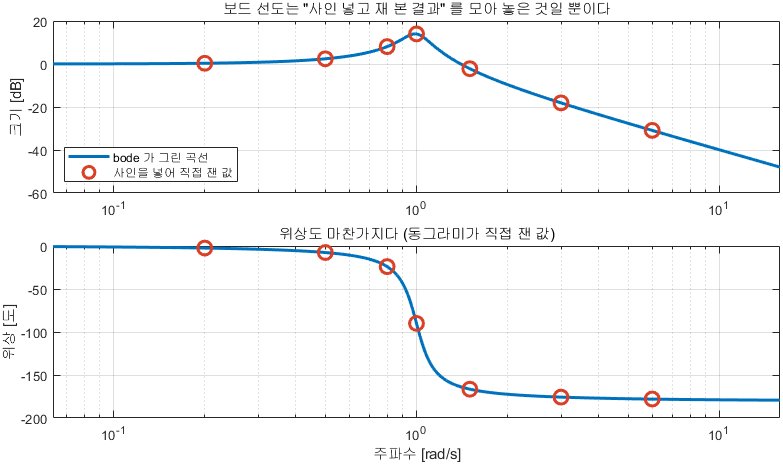

직접 잰 값(동그라미)이 bode 곡선 위에 정확히 놓인다

**그림 파일** `w08_measure.png` — `make_figures.m` 의 `fig_sine_measure` · 다시 만들려면 `make_figures('w08_measure')`

**만드는 곳** — `make_figures.m` 의 `fig_sine_measure` **직접 해 보려면** — `W08_01_sine_to_bode.m` 을 실행하면 `freq_scan` 이 주파수마다 사인을 넣어 재는 과정을 표로 찍어 줍니다

그림 해석

**위아래 두 장이 한 세트입니다.** 크기만 보면 절반만 본 것입니다. 9주차의 안정여유는 이 **아래 그림**에서 나옵니다.

## 3-1. `bode` — 주파수응답을 그리는 명령

**오늘의 새 명령입니다.**

명령 정리

- **원리** — 주파수 $\omega$ 를 훑으며 $G(j\omega)$ 를 계산해 크기와 위상을 그린다

- **입력** — 전달함수. 주파수 벡터를 두 번째 인자로 줄 수도 있다

- **출력** — 출력을 받지 않고 부르면 그림. 출력을 받으면 `[mag, phase, w]` 숫자

주의 세 가지

- 출력으로 받은 `mag` 는 **dB 가 아니라 배율**이다. dB 로 보려면 `20*log10(mag)` 를 직접 해야 한다

- `mag` 와 `phase` 는 3차원 배열로 나온다. `squeeze` 로 눌러야 그릴 수 있다

- 위상은 $\pm 180^\circ$ 를 넘나들며 튈 수 있다. 필요하면 `unwrap` 을 쓴다

G1 = 10/(s*(s+1));
[mg, pg, wg] = bode(G1);
mg = squeeze(mg);  pg = squeeze(pg);
pick = round(linspace(1, numel(wg), 6));   % 촘촘한 주파수 점 가운데 여섯 개만 본다
w_bode   = wg(pick);
mag_bode = mg(pick);
dB_bode  = 20*log10(mag_bode);
ph_bode  = pg(pick);
table(w_bode, mag_bode, dB_bode, ph_bode)
bode(G1); grid on;
title('bode 로 그린 주파수응답');

## 3-2. 보드 선도의 정의 — 두 가지를 바꿔 그린 것

지금까지 그린 그림은 가로축이 **선형**, 세로축이 **배율**이었습니다 (2-3 절 아래 두 칸이 그랬습니다). 손으로 잴 때는 그것이 자연스럽습니다. 그런데 교과서와 MATLAB 이 쓰는 그림은 다릅니다. **축을 두 군데 바꿉니다.**

**정의** — **보드 선도**(Bode plot)는

- **가로축**(주파수)을 **로그 눈금**으로 그리고

- **세로축**(크기)을 **데시벨**(dB)로 그린

주파수응답 그림입니다. 데시벨의 정의는 이 한 줄입니다.


$$|G(j\omega)|_{\mathrm{dB}} = 20 \log_{10} |G(j\omega)|$$


**아래쪽 위상 선도는 바꾸지 않습니다.** 가로축만 같이 로그가 되고, 세로축은 그대로 도(degree) 단위입니다. 위상에는 dB 를 쓰지 않습니다.

기호를 하나씩 풀어 둡니다.

**왜 하필 **$20$** 인가** — 데시벨은 원래 전력의 비에 대해 $10\log_{10}$ 로 정의되었습니다. 그런데 전력은 전압이나 전류의 **제곱**에 비례합니다. 그래서 크기(진폭)의 비를 데시벨로 적으면


$$10 \log_{10} |G|^2 = 20 \log_{10} |G|$$


가 되어 계수가 $20$ 이 됩니다. **제곱이 로그 밖으로 나온 것**입니다.

꼭 외워 둘 값 네 개입니다. 이 네 개만 알면 나머지는 암산이 됩니다.

**부호가 뜻하는 것**

- dB 가 **양수**면 배율이 $1$ 보다 크다 — 그 주파수에서 **키운다**

- dB 가 $0$ 이면 배율이 정확히 $1$ 이다 — **그대로 통과**

- dB 가 **음수**면 배율이 $1$ 보다 작다 — 그 주파수에서 **깎는다**

$0$ dB 선이 특별한 이유가 여기 있습니다. **크기 곡선이 **$0$** dB 선을 지나는 주파수**가 "키우는 것과 깎는 것의 경계" 이고, 그것이 9주차의 **교차주파수** $\omega_c$ 입니다. 이름을 미리 꺼내 두는 이유는, 오늘 그린 $0$ dB 선이 다음 주의 주인공이기 때문입니다.

축을 바꾸면 무엇이 좋아지는지 두 그림을 나란히 놓고 봅니다.

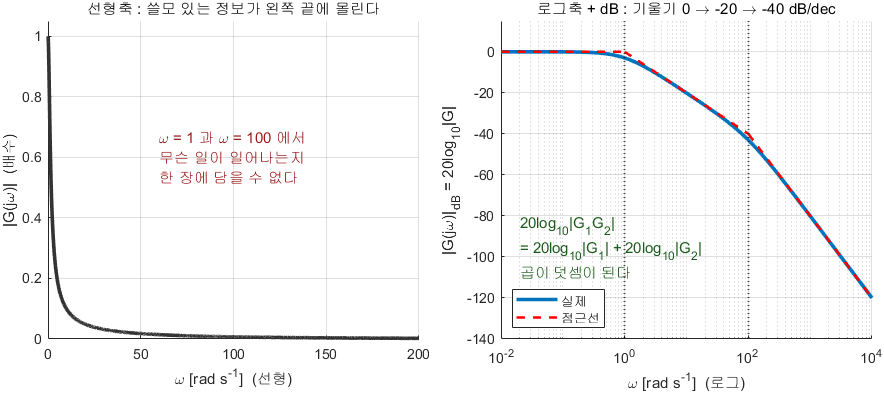

같은 시스템을 선형축과 로그축 더하기 dB 로 그린 것

**그림 파일** `w08_linear_vs_log.png` — `make_figures.m` 의 `fig_w08_linear_vs_log` · 다시 만들려면 `make_figures('w08_linear_vs_log')`

**만드는 곳** — `make_figures.m` 의 `fig_w08_linear_vs_log` **직접 확인해 보려면** — `W08_04_slide_examples.m` 의 **3절**

쓴 시스템은 극점이 $-1$ 과 $-100$ 인 $G(s) = \frac{1}{(s+1)(0.01s+1)}$ 입니다. 극점 두 개가 $100$ 배 떨어져 있다는 것이 요점입니다.

그림 해석

결론을 한 줄로 — **보드 선도는 곡선을 직선 몇 토막으로 바꿔 주는 그림입니다.** 손으로 그릴 수 있게 되고, 기울기만 보고 극점 개수를 셀 수 있게 됩니다.

배율과 dB 를 직접 바꿔 보면 감이 옵니다.

ratio_tbl = [0.001; 0.01; 1/sqrt(2); 1; sqrt(2); 2; 10; 1000];
dB_tbl    = 20*log10(ratio_tbl);          % 배율 -> dB
back_tbl  = 10.^(dB_tbl/20);              % dB -> 배율 (되돌아오는지 확인)
table(ratio_tbl, dB_tbl, back_tbl)

## 4. 왜 dB 이고 왜 로그축인가

두 가지 이유가 있고, 둘 다 실용적인 이유입니다.

**이유 하나 — 곱셈이 덧셈이 된다**


$$20\log_{10}|G_1 G_2| = 20\log_{10}|G_1| + 20\log_{10}|G_2|$$


전달함수는 대개 인수들의 곱입니다. 로그를 취하면 합이 되므로 **조각마다 따로 그린 뒤 세로로 더하면** 전체가 됩니다. 5절의 손작도가 가능한 것이 순전히 이 성질 덕분입니다.

**이유 둘 — 넓은 범위를 한 그림에**

크기가 $1000$ 배 차이 나도 dB 로는 $60$ 차이일 뿐입니다. 주파수도 마찬가지라서 로그축을 씁니다.

ratio = [0.01 0.1 0.5 1/sqrt(2) 1 2 10 100]';   % 배율
dB    = 20*log10(ratio);                        % 데시벨
table(ratio, dB)

## 4-1. 기울기의 단위 — dB per decade

데케이드(decade)는 **주파수가 10 배가 되는 구간**입니다.

- 적분기 $1/s$ : 주파수가 10 배가 되면 크기가 $1/10$ 이 되므로 $-20$ dB $\rightarrow$ **-20 dB per decade**

- 극점이 두 개면 $-40$, 세 개면 $-60$

즉 **기울기를 보면 극점이 몇 개인지 알 수 있습니다.** 이것이 실험 데이터에서 모델을 읽어 내는 첫 단계입니다.

## 5. 손으로 그리기 — 조각은 네 가지뿐

실계수 다항식은 반드시 1차식과 2차식의 곱으로 인수분해됩니다. 그래서 어떤 전달함수든 아래 **네 조각의 곱**입니다.

- **상수** $K$

- **원점의 극점 또는 영점** $s^{\pm n}$ (적분기, 미분기)

- **1차** $(Ts + 1)$

- **2차** $\left(\frac{s}{\omega_n}\right)^2 + 2\zeta\frac{s}{\omega_n} + 1$

조각마다 점근선이 어떻게 생겼는지만 알면 됩니다.

## 5-1. 가장 흔한 실수 — 시정수 꼴로 정리하지 않는 것

$(s+1)$ 과 $(0.1s+1)$ 은 같은 꼴이지만 $(s+10)$ 은 **아닙니다.** 점근선을 그리려면 상수항이 $1$ 이 되도록 먼저 정리해야 합니다.


$$s + 10 = 10\,(0.1\,s + 1)$$


이때 튀어나온 $10$ 은 **상수 조각으로 넘어갑니다.** 이것을 빠뜨리면 그림 전체가 위아래로 어긋납니다.

정리해 보면

Gx = 50/((s+10)*(s+2));
dc_gain = dcgain(Gx)          % 저주파 크기 (w -> 0). 50/(10*2) = 2.5 와 같아야 한다
dc_dB   = 20*log10(dc_gain)   % 데시벨로는 약 8 dB

## 5-2. 조각을 더하면 전체가 된다

아래는 $L(s) = \frac{10}{s(s+1)(0.1s+1)}$ 을 네 조각으로 나눠 그린 뒤 세로로 더한 결과입니다.

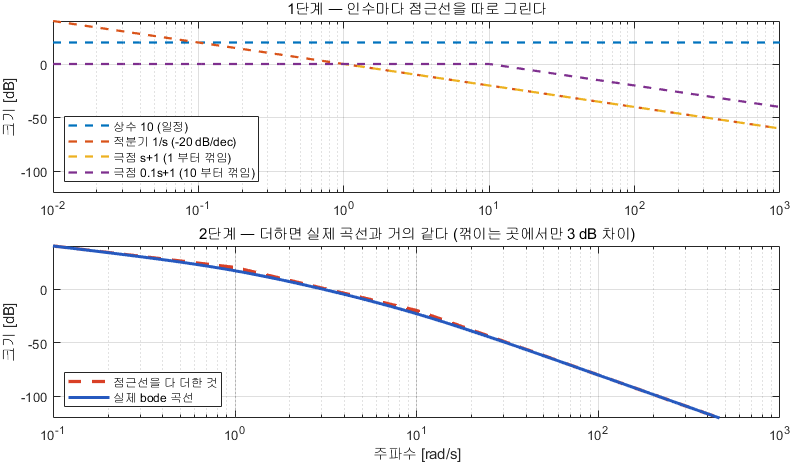

조각마다 그린 뒤 더하면 실제 곡선이 나온다

**그림 파일** `w08_asymptote.png` — `make_figures.m` 의 `fig_bode_asymptote` · 다시 만들려면 `make_figures('w08_asymptote')`

**만드는 곳** — `make_figures.m` 의 `fig_bode_asymptote` **직접 해 보려면** — `W08_02_bode_asymptotes.m` 을 절 단위로 실행하면 조각을 하나씩 얹는 과정을 볼 수 있습니다

그림 해석 — **위 칸에서 조각을 세고, 아래 칸에서 합계를 확인합니다**

**곱셈이 덧셈이 되는 것**이 로그를 쓰는 이유입니다. $G_1 G_2$ 의 dB 값은 $G_1$ 의 dB 와 $G_2$ 의 dB 를 더한 것입니다.

읽을 것

- 꺾임주파수 **밖에서는 점근선이 거의 정확**하다

- 꺾임주파수 **에서만 약 **$3$** dB 어긋난다**

- 그 이유는 1차 극점이 꺾임주파수에서 정확히 $-3.01$ dB 이기 때문이다 ($|1/(j1+1)| = 1/\sqrt{2}$)

L = 10/(s*(s+1)*(0.1*s+1));
w = logspace(-2, 3, 600);
a_sum = 20*log10(10) - 20*log10(w) ...
        - 20*log10(max(w/1,1)) - 20*log10(max(w/10,1));
m_real = 20*log10(squeeze(abs(freqresp(L, w))));
semilogx(w, a_sum, '--', 'LineWidth', 2.5); hold on; grid on;
semilogx(w, m_real, 'LineWidth', 2);
xline(1, ':'); xline(10, ':');
xlabel('주파수 [rad s^{-1}]'); ylabel('크기 [dB]'); ylim([-120 40]);
legend('점근선의 합', '실제 곡선', 'Location','southwest');
title('점근선을 더하면 실제와 거의 같다');
w_check  = [0.1 1 2 10 100]';
asymptote = interp1(log(w), a_sum,  log(w_check));   % 점근선 [dB]
actual    = interp1(log(w), m_real, log(w_check));   % 실제 곡선 [dB]
gap       = actual - asymptote;                      % 차이 [dB]
table(w_check, asymptote, actual, gap)

## 5-3. 위상도 점근선으로 그린다

앞 절에서는 **크기**만 점근선으로 그렸습니다. 그런데 9주차와 10주차에서 실제로 필요한 것은 **위상**입니다. 위상여유가 거기서 나오기 때문입니다. 위상 점근선 규칙을 세웁니다.

크기는 꺾임주파수에서 딱 꺾이지만, **위상은 그렇게 급하게 안 변합니다.** 그래서 규칙이 조금 다릅니다.

**외울 것은 두 가지뿐입니다.**

- 변화는 꺾임주파수의 $1/10$** 에서 시작해 **$10$** 배에서 끝난다** (두 데케이드)

- 꺾임주파수 **바로 그 자리에서 정확히 절반**, 즉 $-45^\circ$

왜 두 데케이드인가 — 1차 극점의 위상은 $-\arctan(\omega/\omega_c)$ 이고, $\omega = 0.1\omega_c$ 에서 $-5.7^\circ$, $\omega = 10\omega_c$ 에서 $-84.3^\circ$ 입니다. 양 끝에서 $0^\circ$ 와 $-90^\circ$ 에 충분히 가까워지므로 그 구간만 직선으로 잇습니다.

앞 절과 같은 $L(s) = \frac{10}{s(s+1)(0.1s+1)}$ 로 그려 봅니다.

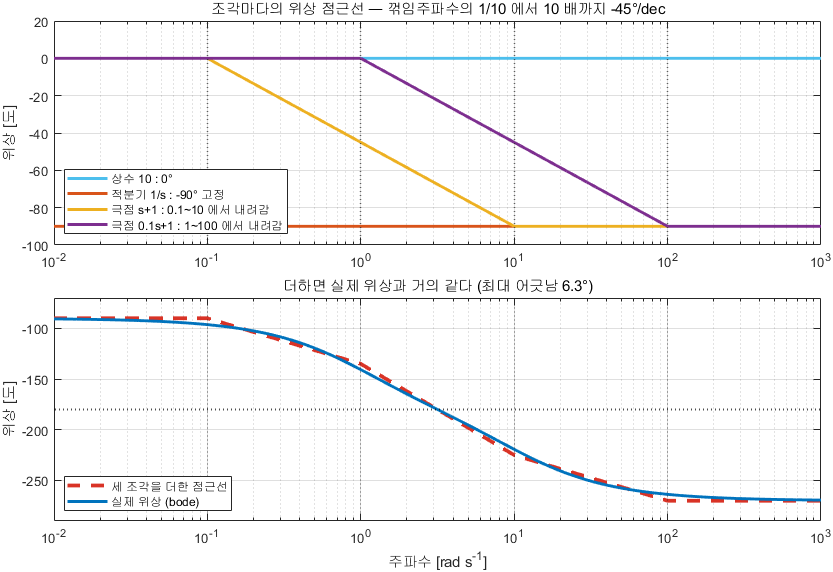

위상도 조각을 더하면 실제와 거의 같다

**그림 파일** `w08_phase_asym.png` — `make_figures.m` 의 `fig_w08_phase_asym` · 다시 만들려면 `make_figures('w08_phase_asym')`

**만드는 곳** — `make_figures.m` 의 `fig_w08_phase_asym` **직접 확인해 보려면** — 아래 코드가 같은 표를 숫자로 찍어 줍니다

그림 해석

아래 표에서 어긋남을 숫자로 확인하십시오.

L5  = 10/(s*(s+1)*(0.1*s+1));
w   = [0.1 0.316 1 3.162 10 31.6 100]';
ph_pole1 = -45*min(max(log10(w/0.1), 0), 2);   % 극점 s+1    (꺾임 1)
ph_pole2 = -45*min(max(log10(w/1  ), 0), 2);   % 극점 0.1s+1 (꺾임 10)
ph_asym  = -90 + ph_pole1 + ph_pole2;          % -90 은 적분기 몫
[~, ph] = bode(L5, w);
ph_real = squeeze(ph);
gap     = ph_real - ph_asym;
table(w, ph_asym, ph_real, gap)

## 5-4. 점근선만으로 교차주파수와 위상여유를 읽는다

**이 절이 손작도를 배우는 이유입니다.** 지금까지 그린 두 점근선만 있으면 다음 두 숫자를 컴퓨터 없이 얻습니다.

- **교차주파수** $\omega_c$ — 크기 점근선이 $0$ dB 를 지나는 곳

- **위상여유** $PM$ — 그 자리에서 위상을 읽고 $180^\circ$ 를 더한 값

두 숫자가 9주차와 10주차의 전부입니다.

우리 예제로 해 봅니다. 크기 점근선은 $1 < \omega < 10$ 구간에서


$$20\log_{10}10 - 20\log_{10}\omega - 20\log_{10}\omega = 20 - 40\log_{10}\omega$$


이것이 $0$ 이 되는 곳은 $\log_{10}\omega = 0.5$, 즉 $\omega_c = \sqrt{10} = 3.16$ 입니다. (구한 값이 정말 $1 \sim 10$ 안에 있는지 **반드시 확인**하십시오. 다른 구간의 식을 썼다면 답이 그 구간 밖으로 나옵니다.)

그 자리에서 위상 점근선을 읽으면


$$-90^\circ - 45^\circ\log_{10}\frac{3.16}{0.1} - 45^\circ\log_{10}\frac{3.16}{1} = -90^\circ - 67.5^\circ - 22.5^\circ = -180^\circ$$


따라서 $PM = 180^\circ - 180^\circ = 0^\circ$ 입니다. **이 루프는 거의 불안정합니다.**

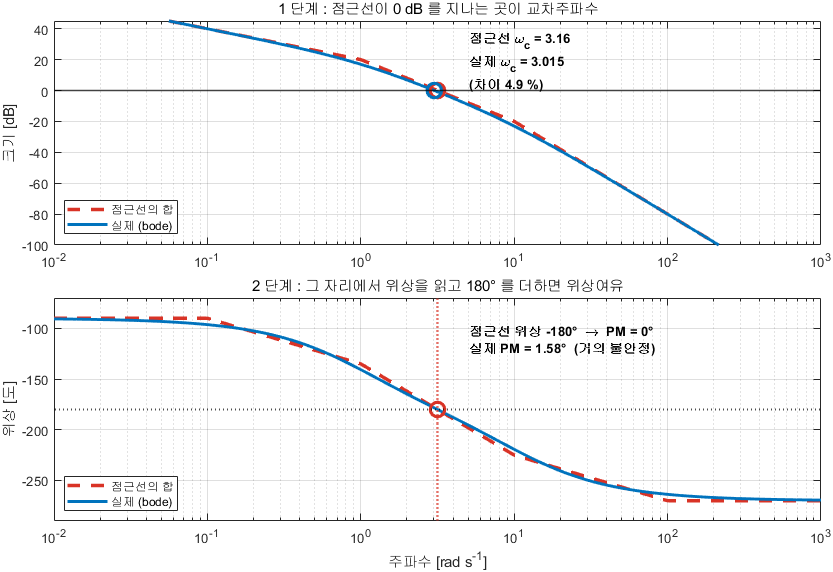

점근선 두 장으로 교차주파수와 위상여유를 읽는다

**그림 파일** `w08_hand_margin.png` — `make_figures.m` 의 `fig_w08_hand_margin` · 다시 만들려면 `make_figures('w08_hand_margin')`

**만드는 곳** — `make_figures.m` 의 `fig_w08_hand_margin` **직접 확인해 보려면** — 아래 코드가 `margin` 으로 검산합니다

그림 해석

손으로 그린 것과 `margin` 이 준 것이 **같은 결론을 냅니다.** 이것이 손작도를 배우는 이유입니다. 플랜트를 잘못 입력했거나 부호를 틀렸을 때, 손으로 어림잡을 수 있으면 이상한 결과를 그대로 믿지 않게 됩니다.

w_hand  = 10^0.5;
ph_hand = -90 - 45*log10(w_hand/0.1) - 45*log10(w_hand/1);
[~, pm_margin, ~, wc_margin] = margin(L5);
wc_hand = w_hand              % 손으로 읽은 교차주파수 [rad/s]
wc_margin                     % margin 이 구한 값

pm_hand = 180 + ph_hand       % 손으로 읽은 위상여유 [도]
pm_margin                     % margin 이 구한 값

## 5-5. 이득 $K$ 를 바꾸면 — 크기만 통째로 위아래, 위상은 꼼짝도 안 한다

**이 절이 8주차에서 설계와 가장 직접 이어지는 곳입니다.**

설계할 때 우리가 손으로 돌리는 다이얼은 대개 **이득 하나**입니다. 그 다이얼을 돌리면 보드 선도가 어떻게 움직이는지 알면, 그림을 다시 그리지 않고도 결과를 예측할 수 있습니다.

**비유** — 확성기의 볼륨 노브입니다. 볼륨을 올리면 소리가 **전체적으로** 커집니다. 저음만 커지거나 고음만 커지는 것이 아니고, **음악의 모양** (어느 음이 언제 나오는지)도 전혀 바뀌지 않습니다. 이득 $K$ 가 바로 그 노브입니다.

**왜 그런가 — 크기 쪽 유도**

이득 $K$ 를 곱한 시스템 $KG(s)$ 의 크기를 dB 로 적습니다.

- **1단계** 복소수의 곱의 크기는 크기의 곱입니다 — $|KG(j\omega)| = K\,|G(j\omega)|$ ($K > 0$ 이므로 $|K| = K$)

- **2단계** 양변에 $20\log_{10}$ 을 취합니다

- **3단계** 로그는 곱을 합으로 바꿉니다 (4절의 그 성질입니다)


$$20 \log_{10} |K G(j\omega)| = 20 \log_{10} K + 20 \log_{10} |G(j\omega)|$$


오른쪽을 보십시오. $20\log_{10}K$** 는 **$\omega$** 와 무관한 상수**입니다. 즉 원래 곡선에 **모든 주파수에서 똑같은 값**이 더해집니다. 함수에 상수를 더하는 것은 그래프를 **위아래로 평행이동**하는 것입니다.

**결론 1 — 크기 선도는 모양이 전혀 바뀌지 않고, 통째로 위아래로만 움직입니다.** 꺾이는 자리도 그대로, 기울기도 그대로입니다.

**왜 그런가 — 위상 쪽 유도**

- **1단계** 복소수의 곱의 위상은 위상의 합입니다 — $\angle(KG) = \angle K + \angle G$

- **2단계** $K$ 는 **양의 실수**입니다. 복소평면에서 양의 실수축 위에 있으므로 그 위상은 $0^\circ$ 입니다

- **3단계** 그러므로 더해지는 것이 없습니다


$$\angle K G(j\omega) = \angle G(j\omega) \qquad (K > 0)$$


**결론 2 — 위상 선도는 **$K$** 를 아무리 바꿔도 전혀 움직이지 않습니다.**

평행이동하는 양을 손으로 계산해 둡니다.

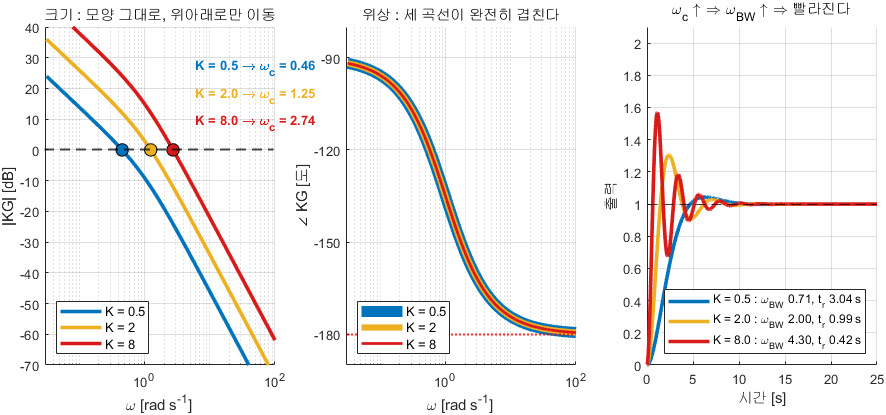

K 를 바꾸면 크기는 평행이동, 위상은 그대로, 그래서 응답이 빨라진다

**그림 파일** `w08_gain_shift.png` — `make_figures.m` 의 `fig_w08_gain_shift` · 다시 만들려면 `make_figures('w08_gain_shift')`

**만드는 곳** — `make_figures.m` 의 `fig_w08_gain_shift` **직접 확인해 보려면** — `W08_04_slide_examples.m` 의 **4절**

쓴 시스템은 $G(s) = \frac{1}{s(s+1)}$ 이고 $K = 0.5,\ 2,\ 8$ 세 가지입니다.

그림 해석

**그래서 무엇이 좋아지는가 — 이 과목의 핵심 연쇄입니다**

왼쪽 칸과 오른쪽 칸을 이으면 이렇게 됩니다.

- 이득을 키우면 크기 선도가 **올라갑니다**

- 올라간 곡선은 $0$ dB 선을 **더 오른쪽에서** 만납니다 $\rightarrow$ $\omega_c$ 가 커진다

- $\omega_c$ 가 커지면 폐루프의 **대역폭** $\omega_{BW}$ 도 같이 커집니다 (9주차에서 $\omega_c \le \omega_{BW} \le 2\omega_c$ 임을 배웁니다)

- 대역폭이 커지면 **빠른 지령까지 따라갈 수 있게** 되므로 응답이 빨라집니다

$K$** 를 키우면 **$\Rightarrow$ $\omega_c$** 커짐 **$\Rightarrow$ $\omega_{BW}$** 커짐 **$\Rightarrow$ $t_r$**, **$t_s$**, **$T_p$** 줄어듦 (= 응답이 빨라짐)**

**반응속도를 올리고 싶으면 대역폭(또는 교차주파수)을 올려야 합니다.** 이것이 주파수영역 설계의 출발점이고, 10주차에서 보상기를 설계하는 이유입니다. 눈대중으로 쓰는 식은 이것입니다.


$$t_r \approx \frac{1.8}{\omega_{BW}}$$


그림의 숫자로 확인해 보면 — $\omega_{BW} = 4.30$ 일 때 $1.8/4.30 = 0.42$ 초이고, 실제로 잰 상승시간이 $0.42$ 초입니다.

**대가 — 공짜가 아닙니다**

여기서 위상 선도가 **안 움직인다**는 사실이 되돌아옵니다.

- 교차주파수 $\omega_c$ 는 오른쪽으로 갔는데

- 위상 곡선은 그대로이므로, **더 오른쪽의 위상값**을 보게 됩니다

- 이 시스템의 위상은 오른쪽으로 갈수록 $-180^\circ$ 에 가까워집니다

- 그러므로 $-180^\circ$ 까지 남은 여유가 **줄어듭니다** (위상여유 감소)

- 위상여유가 줄면 감쇠비가 작아지고 **오버슈트가 커집니다**

오른쪽 칸의 빨간 곡선이 출렁이는 이유가 바로 이것입니다. 그래서 설계는 늘 **빠름과 출렁임 사이의 맞바꿈**이 됩니다. 9주차에서 이 맞바꿈을 숫자로 재고, 10주차에서 위상을 **보태 주는** 보상기로 맞바꿈 자체를 옮기는 법을 배웁니다.

**주의 — **$K$** 가 음수면 이야기가 다릅니다**

위 결론 2 는 $K > 0$ 일 때만 참입니다. $K < 0$ 이면 복소평면에서 음의 실수축에 놓이므로 $\angle K = \pm 180^\circ$ 이고, **위상 선도가 통째로 **$180^\circ$** 만큼 이동합니다.** 크기는 $|K|$ 로 계산하므로 그대로입니다. 부호를 잘못 넣으면 안정했던 시스템이 불안정해지는 사고가 여기서 납니다.

평행이동을 숫자로 확인합니다.

G_k  = 1/(s*(s+1));
K_k  = [0.5; 2; 8];
w_k  = 1;                                  % 한 주파수에서만 재 본다

mag_G_dB = 20*log10(abs(freqresp(G_k, w_k)));        % 원래 곡선의 값 [dB]
shift_dB = 20*log10(K_k);                            % 더해질 상수 [dB]
pred_dB  = mag_G_dB + shift_dB;                      % 예상 [dB]

meas_dB  = zeros(3,1);  meas_ph = zeros(3,1);  wc_k = zeros(3,1);
for i = 1:3
    Gi          = K_k(i) * G_k;
    meas_dB(i)  = 20*log10(abs(freqresp(Gi, w_k)));  % 실제로 잰 크기 [dB]
    meas_ph(i)  = angle(freqresp(Gi, w_k)) * 180/pi; % 실제로 잰 위상 [도]
    [~, ~, ~, wc_k(i)] = margin(Gi);                 % 교차주파수
end

table(K_k, shift_dB, pred_dB, meas_dB, meas_ph, wc_k)

% 위상이 정말 안 움직이는지 — 세 값의 차이가 0 이어야 한다
phase_spread = max(meas_ph) - min(meas_ph)

## 5-6. 교차주파수와 대역폭 — 이름이 둘인 이유

왜 필요한가 — 앞 절에서 "$\omega_c$ 가 커지면 $\omega_{BW}$ 도 커져서 빨라진다" 고 적었습니다. 그런데 **왜 이름이 둘인지**, 그리고 둘이 왜 같이 움직이는지는 아직 말하지 않았습니다. 여기서 짚고 넘어갑니다. 자세한 식과 설계 활용은 $10$주차와 $11$주차에서 다룹니다.

두 주파수는 **서로 다른 함수의, 서로 다른 기준선**을 읽은 것입니다.

**왜 **$-3$** dB 인가** — 신호의 전력은 진폭의 제곱에 비례합니다. 크기가 $1/\sqrt{2}$ 로 떨어지면 전력은 그 제곱인 $1/2$, 즉 **절반**입니다.


$$20\log_{10}\frac{1}{\sqrt{2}} = -10\log_{10} 2 = -3.01 \text{ dB}$$


"절반의 전력만 남는 곳까지는 통과시킨 것으로 본다" 는 약속입니다. 통신에서 넘어온 관례인데 제어에서도 그대로 씁니다.

**둘이 왜 같이 움직이는가** — 식 하나로 설명됩니다. $T = L/(1+L)$ 의 크기를 쓰면


$$|T(j\omega)| = \frac{|L(j\omega)|}{|1 + L(j\omega)|}$$


여기서 $\omega = \omega_c$ 를 넣습니다. $\omega_c$ 의 정의가 $|L(j\omega_c)| = 1$ 이므로 분자가 $1$ 이 되어 사라집니다.


$$|T(j\omega_c)| = \frac{1}{|1 + L(j\omega_c)|}$$


이제 분모만 남았습니다. $|L| = 1$ 이고 위상을 $\theta = \angle L(j\omega_c)$ 라 하면 $L(j\omega_c) = \cos\theta + j\sin\theta$ 이므로


$$|1 + L(j\omega_c)| = \sqrt{(1+\cos\theta)^2 + \sin^2\theta} = \sqrt{2 + 2\cos\theta}$$


반각 공식 $1 + \cos\theta = 2\cos^2(\theta/2)$ 를 쓰면 깔끔해집니다.


$$|1 + L(j\omega_c)| = 2\left|\cos\frac{\theta}{2}\right| \quad \Rightarrow \quad |T(j\omega_c)| = \frac{1}{2\left|\cos(\theta/2)\right|}$$


위상여유의 정의 $\text{PM} = 180^\circ + \theta$ 를 넣어 $\theta$ 를 없애면, $\omega_c$** 에서의 폐루프 크기가 위상여유만으로 정해집니다.**

표의 마지막 두 줄이 답을 줍니다.

- PM 이 $90^\circ$ 보다 **작으면** $\omega_c$ 에서 폐루프는 아직 $-3$ dB 에 닿지 않았습니다. 그러므로 $-3$ dB 는 **더 오른쪽**에 있습니다 $\rightarrow$ $\omega_{BW} > \omega_c$

- PM 이 정확히 $90^\circ$ 일 때만 둘이 **같아집니다**

- 실제 설계의 PM 은 보통 $30^\circ \sim 70^\circ$ 입니다. 그러므로 $\omega_{BW}$** 는 늘 **$\omega_c$** 보다 조금 크다**

그리고 $|T|$ 가 $0$ dB 부근에서 $-3$ dB 까지 떨어지는 데 걸리는 거리는 보드 선도에서 한 옥타브도 안 됩니다. 그래서 두 주파수가 **비례처럼 붙어서 움직입니다.** $10$주차에서 이 비율을 $\zeta$ 만의 식으로 정확히 계산해 보면 $1.4$ 와 $1.62$ 사이에 있다는 것이 나옵니다.

**물리적 해석** — 같은 "빠르기" 를 두 자리에서 재는 것입니다.

- $\omega_c$ 는 **루프 안쪽**에서 잰 값입니다. "되먹임이 아직 힘을 쓰는 범위" 의 끝입니다. $\omega < \omega_c$ 에서는 $|L| > 1$ 이라 오차를 눌러 주고, $\omega > \omega_c$ 에서는 $|L| < 1$ 이라 손을 놓습니다

- $\omega_{BW}$ 는 **밖에서** 잰 값입니다. 사용자는 루프 속을 못 봅니다. 지령을 흔들어 보고 출력이 따라오는지만 봅니다

- 되먹임이 힘을 쓰는 범위가 넓어지면, 밖에서 본 따라가는 범위도 같이 넓어집니다. 그래서 둘은 **같은 하나**를 다른 자리에서 본 것입니다

숫자로 확인합니다. $\zeta = 0.5$ 인 표준 2차 루프를 씁니다.

s    = tf('s');                          % 이 절만 떼어 돌려도 되게 다시 선언
L_bw = 1/(s*(s + 2*0.5));                % 표준 2차 개루프 (wn = 1, zeta = 0.5)
T_bw = feedback(L_bw, 1);                % 폐루프

[~, PM_bw, ~, wc_bw] = margin(L_bw);     % 개루프에서 읽는 교차주파수
wbw_bw = bandwidth(T_bw);                % 폐루프에서 읽는 대역폭

th_bw      = (-180 + PM_bw) * pi/180;            % wc 에서의 개루프 위상 [rad]
Tc_formula = 1 / (2*abs(cos(th_bw/2)));          % 위에서 유도한 식
Tc_direct  = abs(freqresp(T_bw, wc_bw));         % 직접 잰 값

table(PM_bw, wc_bw, wbw_bw, wbw_bw/wc_bw, Tc_formula, Tc_direct, ...
    'VariableNames', {'PM', 'wc', 'wBW', '비율', '식으로', '직접잰값'})

읽을 것 세 가지입니다.

- **식으로** 와 **직접잰값** 이 같습니다. 위 유도가 맞았습니다

- PM 이 $51.8^\circ$ 로 $90^\circ$ 보다 작으므로 $\omega_c$ 에서 폐루프는 $1.144$ 배 ($+1.17$ dB) 입니다. 아직 $-3$ dB 가 아니므로 $\omega_{BW}$ 는 더 오른쪽입니다

- 비율이 $1.62$ 입니다. $\omega_c$ 만 알아도 대역폭의 **자리**는 압니다

왜 중요한가 — 사양서가 "대역폭 $60$ rad/s 이상" 으로 오면, 설계는 보드 선도에서 $\omega_c$** 를 약 **$40$** rad/s 로 맞추는 일**로 번역됩니다. 그리고 $\omega_c$ 를 옮기는 가장 간단한 손잡이가 바로 앞 절의 **이득 **$K$ 입니다. $10$주차에서 이 번역을 정확한 식으로 하고, $11$주차에서 $K$ 말고 다른 손잡이들을 배웁니다.

## 6. 2차 항의 봉우리

점근선만 그리면 놓치는 것이 하나 있습니다. **2차 항의 봉우리**입니다.

2차 표준형에 $s = j\omega_n$ 을 넣어 보면 실수부가 서로 상쇄되고 허수부만 남습니다.


$$T(j\omega_n) = \frac{\omega_n^2} {(j\omega_n)^2 + 2\zeta\omega_n(j\omega_n) + \omega_n^2} = \frac{\omega_n^2}{2j\zeta\omega_n^2} = \frac{1}{2j\zeta}$$


즉 $|T(j\omega_n)| = \frac{1}{2\zeta}$ 입니다. **감쇠비가 작을수록 이 값이 커집니다.** 그것이 봉우리입니다.

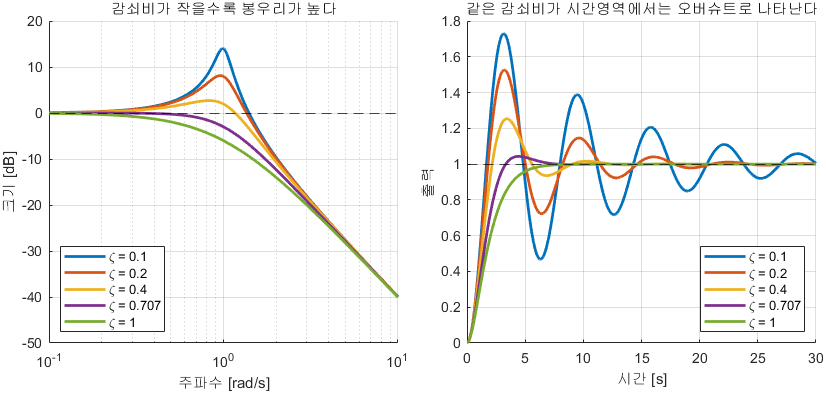

감쇠비가 작을수록 봉우리가 높고, 시간영역에서는 오버슈트가 크다

**그림 파일** `w08_resonance.png` — `make_figures.m` 의 `fig_resonance` · 다시 만들려면 `make_figures('w08_resonance')`

**만드는 곳** — `make_figures.m` 의 `fig_resonance` **직접 바꿔 보려면** — `W08_02_bode_asymptotes.m` 의 마지막 절에서 `zeta` 목록을 바꿔 실행

그림 해석 — **왼쪽 곡선과 오른쪽 곡선을 색으로 짝지어 읽으십시오**

왼쪽과 오른쪽은 **같은 사실을 두 언어로 적은 것**입니다. 주파수영역의 "봉우리" 가 시간영역의 "오버슈트" 입니다. 9주차에서 이 대응을 $\zeta \approx \mathrm{PM}/100$ 이라는 공식으로 만듭니다.

## 6-1. 봉우리와 오버슈트는 같은 이야기다

4주차에서 배운 것과 연결됩니다.

- 시간영역 : $\zeta$ 가 작으면 **오버슈트**가 크다

- 주파수영역 : $\zeta$ 가 작으면 **봉우리**가 크다

같은 성질을 두 각도에서 보는 것뿐입니다.

정확한 봉우리 값과 그 위치는 이렇습니다 ($\zeta < 0.707$ 일 때만 존재).


$$M_r = \frac{1}{2\zeta\sqrt{1-\zeta^2}}, \qquad \omega_r = \omega_n\sqrt{1 - 2\zeta^2}$$


$\zeta \ge 0.707$ 이면 봉우리가 아예 없습니다. 이 값이 실무에서 자주 쓰이는 이유입니다.

zeta = [0.1 0.2 0.3 0.5 0.707 1.0]';
Mr_dB = 20*log10(1./(2*zeta.*sqrt(1-zeta.^2)));   % 봉우리 높이 [dB]
Mr_dB(zeta >= 1/sqrt(2)) = NaN;                   % 0.707 이상이면 봉우리가 없다
OS = zeros(size(zeta));                           % 오버슈트 [%]
for i = 1:numel(zeta)
    OS(i) = stepinfo(1/(s^2 + 2*zeta(i)*s + 1)).Overshoot;
end
table(zeta, Mr_dB, OS)

## 7. 필터 — 주파수로 신호를 골라내기

지금까지는 시스템을 "제어 대상" 으로만 봤습니다. 그런데 같은 전달함수를 **신호를 골라내는 도구**로 쓸 수도 있습니다. 그것이 필터입니다.

왜 지금 필터를 다루는가 — 세 가지가 오늘 배운 것과 그대로 이어집니다.

- 필터는 **주파수마다 다르게 통과시키는 것**이다. 곧 크기 응답 그 자체다

- 무엇을 통과시키고 무엇을 막을지는 **보드 선도로 정한다**

- 그리고 **공짜가 아니다.** 막는 대신 위상이 늦는다

마지막 항목이 이 과목에서 가장 중요합니다. 7주차에서 미분항의 잡음을 잡으려고 필터를 붙였고, 10주차에서 Lead 와 Lag 를 쓸 때 같은 맞바꿈을 다시 만납니다.

## 7-1. 저역통과 필터 — 느린 것은 통과, 빠른 것은 차단

가장 많이 쓰는 필터입니다. 1차 저역통과는 이렇게 생겼습니다.


$$G(s) = \frac{1}{\tau s + 1} = \frac{\omega_0}{s + \omega_0}, \qquad \omega_0 = \frac{1}{\tau}$$


기호를 정리해 두겠습니다.

세 가지가 **같은 하나**를 다르게 부르는 것입니다. 하나를 정하면 나머지가 정해집니다.

## 7-2. 실제로 어떻게 되는가 — 네 칸으로 함께 보기

왼쪽 두 칸은 **주파수영역**, 오른쪽 두 칸은 **시간영역**입니다. 같은 필터를 두 눈으로 보는 것입니다.

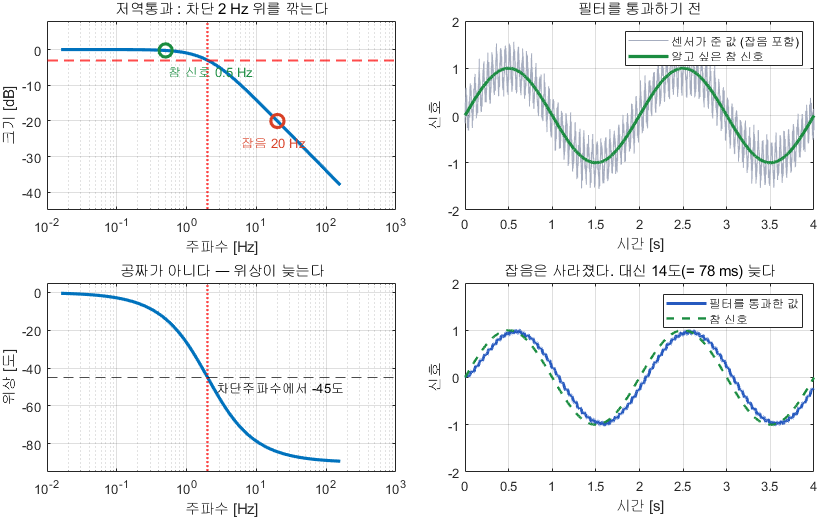

저역통과 : 왼쪽은 주파수, 오른쪽은 시간

**그림 파일** `w08_lpf.png` — `make_figures.m` 의 `fig_lpf` · 다시 만들려면 `make_figures('w08_lpf')`

**만드는 곳** — `make_figures.m` 의 `fig_lpf` **직접 바꿔 보려면** — 함수 안의 차단주파수 $2$ Hz 를 $0.8$ 이나 $5$ 로 바꾸면 네 칸이 함께 움직입니다

그림 해석 — **왼쪽 두 칸이 주파수 이야기, 오른쪽 두 칸이 시간 이야기입니다**

**공짜가 아닙니다.** 잡음을 없앤 대가로 신호가 $78$ ms 늦어졌습니다. 제어 루프 안에 필터를 넣으면 이 지연이 **위상여유를 깎습니다** (9주차). 그래서 필터는 세게 걸수록 좋은 것이 아닙니다.

왼쪽 위에서 읽을 것

- 참 신호 $0.5$ Hz 는 차단주파수($2$ Hz)보다 **아래**라 거의 그대로 지나간다 (초록 동그라미)

- 잡음 $20$ Hz 는 차단주파수보다 **위**라 $-20$ dB, 즉 **십분의 일**로 줄어든다 (빨간 동그라미)

오른쪽에서 읽을 것

- 통과 전에는 참 신호가 잡음에 덮여 있다

- 통과 후에는 잡음이 사라지고 참 신호가 드러난다

- **다만 조금 늦다.** 이것이 왼쪽 아래 위상 그림이 말해 주던 것이다

늦는 양은 계산할 수 있습니다. $0.5$ Hz 에서 위상이 $-14^\circ$ 이므로


$$\text{지연} = \frac{14^\circ}{360^\circ} \times \frac{1}{0.5\,\mathrm{Hz}} \approx 78\ \mathrm{ms}$$


## 7-3. 강의자료의 예제를 그대로

이 과목의 강의자료(부록 14쪽)에 같은 예제가 **이산 필터**로 나옵니다.


$$y(k) = a\,y(k-1) + (1-a)\,u(k), \qquad a = 0.99$$


이것은 "예전 값을 $99\%$, 새 값을 $1\%$ 씩 섞는다" 는 뜻입니다. 새 값을 조금씩만 반영하니 갑작스러운 변화(잡음)가 눌립니다.

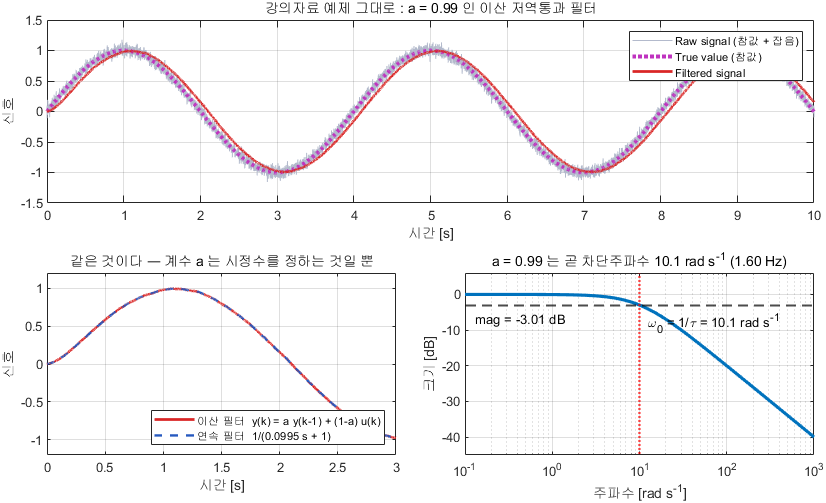

강의자료 14쪽 예제를 그대로 재현했다

**그림 파일** `w08_lpf_prof.png` — `make_figures.m` 의 `fig_lpf_prof` · 다시 만들려면 `make_figures('w08_lpf_prof')`

**만드는 곳** — `make_figures.m` 의 `fig_lpf_prof` **직접 바꿔 보려면** — 함수 안의 `a = 0.99` 를 `0.9` 나 `0.999` 로 바꾸면 세 칸이 함께 움직입니다

그림 해석

실무에서 마이크로컨트롤러에 필터를 넣을 때 쓰는 것이 아래 왼쪽의 **한 줄짜리 이산 필터**입니다. 이 강의에서 배운 $1/(\tau s + 1)$ 과 정확히 같은 것이라는 점을 확인해 두십시오.

위 칸이 강의자료의 그림입니다. `Raw signal`, `True value`, `Filtered signal` 세 개가 그대로 나옵니다. 아래 두 칸은 **오늘 배운 것과 잇기 위해** 덧붙인 것입니다.

- 왼쪽 아래 : 이 이산 필터가 사실 $1/(\tau s + 1)$ 과 **같은 것**임을 보인다

- 오른쪽 아래 : 그 필터의 보드 선도. 계수 $a$ 가 곧 차단주파수를 정한다

이산 계수 $a$ 와 시정수의 관계는 이렇습니다.


$$\tau = \frac{-\Delta t}{\ln a}$$


dt  = 0.001;                  % 샘플 주기 [s]
a   = [0.90 0.95 0.99 0.999]';
tau = -dt./log(a);            % 연속 시정수 [s]
w0  = 1./tau;                 % 차단주파수 [rad/s]
f0  = w0/(2*pi);              % 차단주파수 [Hz]
table(a, tau, w0, f0)

읽는 법

- $a$ 를 $1$ 에 가깝게 할수록 시정수가 커집니다. **더 매끄럽고 더 늦습니다**

- $a = 0.99$ 는 차단주파수 $1.6$ Hz 짜리 필터입니다

- 같은 $a$ 라도 **샘플 주기가 다르면 다른 필터**가 됩니다. 반드시 $dt$ 와 함께 적으십시오

## 7-4. 시정수를 눈으로 읽는 법

강의자료 17쪽의 그림입니다. 계단을 넣고 $\tau$ 를 바꿔 가며 본 것입니다.

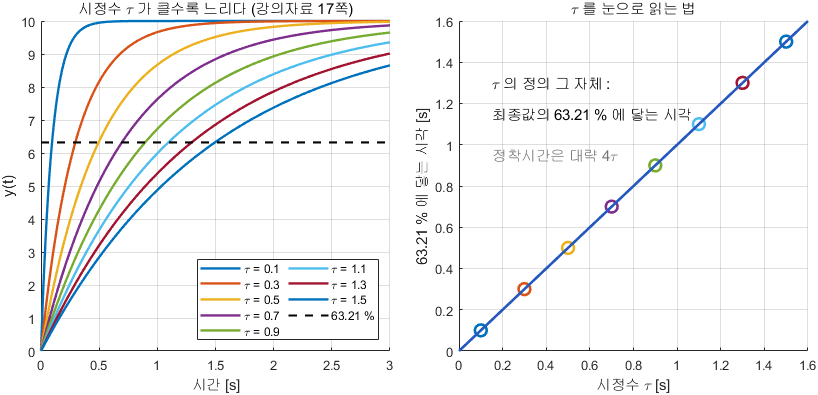

시정수가 클수록 느리다 (강의자료 17쪽)

**그림 파일** `w08_tau_time.png` — `make_figures.m` 의 `fig_tau_time` · 다시 만들려면 `make_figures('w08_tau_time')`

**만드는 곳** — `make_figures.m` 의 `fig_tau_time` **직접 바꿔 보려면** — 함수 안의 `taus` 목록에 $2.0$ 을 추가해 보십시오

그림 해석

실험 데이터에서 $\tau$ 를 읽는 법이 여기 있습니다. **최종값의 **$63\%$** 에 닿는 시각을 자로 재면 그것이 **$\tau$** 입니다.** 모델을 몰라도 됩니다.

$\tau$ 의 정의는 이것입니다.

**최종값의 **$63.21\%$** 에 닿는 시각.**

왜 하필 $63.21\%$ 인가 — 1차 계단응답이 $y(t) = y_c(1 - e^{-t/\tau})$ 이므로 $t = \tau$ 를 넣으면


$$y(\tau) = y_c\left(1 - e^{-1}\right) = 0.6321\,y_c$$


4주차에서 배운 것과 같은 이야기입니다. 정착시간은 대략 $4\tau$ 입니다.

## 7-5. 같은 것을 주파수로 보면

강의자료 19쪽의 그림입니다. 같은 $\tau$ 들을 주파수영역에서 본 것입니다.

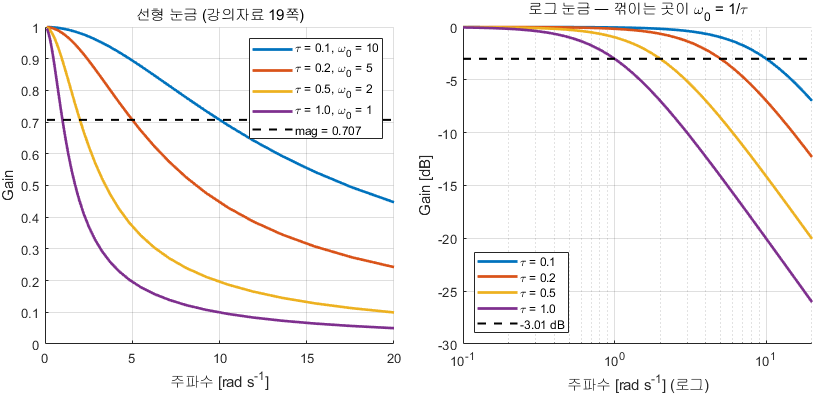

시정수별 주파수응답 (강의자료 19쪽)

**그림 파일** `w08_tau_freq.png` — `make_figures.m` 의 `fig_tau_freq` · 다시 만들려면 `make_figures('w08_tau_freq')`

**만드는 곳** — `make_figures.m` 의 `fig_tau_freq` **직접 바꿔 보려면** — 앞 그림 `fig_tau_time` 과 같은 `taus` 를 쓰므로 둘을 함께 바꿔 보면 대응이 분명해집니다

그림 해석 — **같은 내용을 선형 눈금과 로그 눈금으로 두 번 그린 것입니다**

앞 그림(시간)과 이 그림(주파수)은 **같은 **$\tau$** 를 두 방향에서 본 것**입니다. $\tau$ 가 작으면 시간영역에서는 빨리 오르고, 주파수영역에서는 넓게 통과시킵니다.

왼쪽은 선형 눈금이라 $0.707$ 선을, 오른쪽은 로그 눈금이라 $-3.01$ dB 선을 그었습니다. **같은 선입니다.**


$$20\log_{10} \frac{1}{\sqrt{2}} = 20\log_{10} 0.7071 = -3.01\ \mathrm{dB}$$


그리고 그 선을 지나는 자리가 $\omega_0 = 1/\tau$ 입니다.

**시간영역의 **$\tau$** 와 주파수영역의 **$\omega_0$** 는 같은 숫자의 앞뒷면입니다.** $\tau$ 를 두 배로 하면 $\omega_0$ 가 절반이 되고, 응답은 두 배 느려집니다.

tau = [0.1 0.2 0.5 1.0]';
w0  = 1./tau;                 % 차단주파수 [rad/s]
ts_approx = 4*tau;            % 4주차의 어림 정착시간 [s]
ts_real = zeros(size(tau));   % 실제 정착시간
bw      = zeros(size(tau));   % 실제 대역폭
for i = 1:numel(tau)
    G = 1/(tau(i)*s + 1);
    ts_real(i) = stepinfo(G).SettlingTime;
    bw(i)      = bandwidth(G);
end
table(tau, w0, ts_approx, ts_real, bw)

$4\tau$ 어림과 실제 정착시간이 잘 맞고, 대역폭도 $1/\tau$ 와 거의 같습니다. 1차 시스템에서는 **시정수와 차단주파수가 같은 것의 앞뒷면**입니다.

## 7-6. 차단주파수를 어디에 둘 것인가 — 맞바꿈

이것이 필터 설계의 전부입니다. **낮추면 조용하지만 느리고, 높이면 빠르지만 시끄럽습니다.**

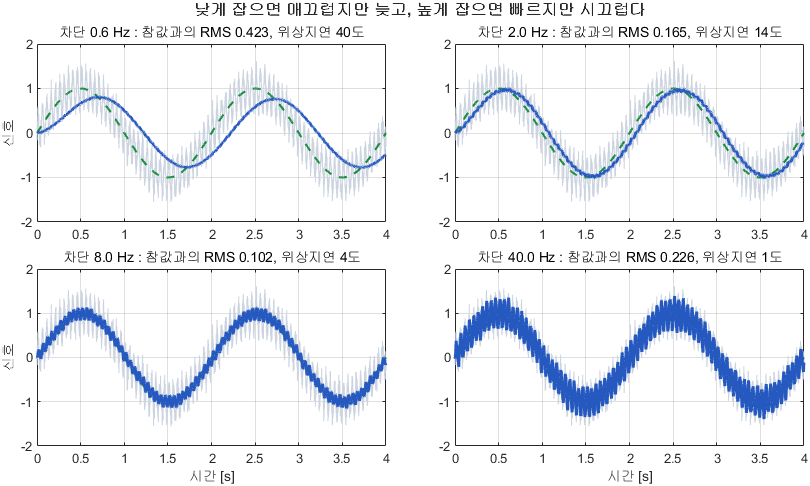

차단주파수를 바꿔 가며 같은 신호를 걸러 본 것

**그림 파일** `w08_cutoff.png` — `make_figures.m` 의 `fig_cutoff_tradeoff` · 다시 만들려면 `make_figures('w08_cutoff')`

**만드는 곳** — `make_figures.m` 의 `fig_cutoff_tradeoff` **직접 바꿔 보려면** — 함수 안의 차단주파수 목록 `[0.6 2 8 40]` 을 바꿔 실행

그림 해석 — **네 칸의 제목에 있는 두 숫자를 함께 보십시오**

**양 끝이 다 나쁘고 가운데가 좋다** — 이것이 맞바꿈입니다. 낮게 잡으면 신호까지 깎이고 늦어지며, 높게 잡으면 잡음이 그대로 들어옵니다. "필터를 세게 걸면 좋다" 는 흔한 오해를 이 그림이 정면으로 반박합니다.

네 칸의 숫자를 보면 최적이 가운데 어딘가에 있습니다.

- 차단 $0.6$ Hz — 아주 매끄럽지만 참값과의 오차가 가장 크다. **너무 늦어서** 그렇다

- 차단 $8$ Hz — 이 네 개 중에서는 오차가 가장 작다

- 차단 $40$ Hz — 잡음이 거의 그대로 통과해 오차가 다시 커진다

**그림의 네 개만 보고 고르면 안 됩니다.** 아래 표처럼 촘촘히 훑어 보면 실제 최적은 그 사이($4$ Hz 근처)에 있습니다. 필터 설계도 6~7주차의 이득 선정과 똑같이 **훑어서 고르는 일**입니다.

**고르는 원칙 하나** — 참 신호의 최고 주파수보다는 위에, 잡음의 최저 주파수보다는 아래에. 둘이 겹치면 필터로는 분리할 수 없습니다. 그때는 센서를 바꾸거나 다른 정보를 함께 써야 합니다 (칼만 필터가 그 이야기입니다).

t     = (0:0.001:4)';
clean = sin(2*pi*0.5*t);                                    % 참값 (0.5 Hz)
rng(11);
noisy = clean + 0.35*sin(2*pi*20*t) + 0.12*randn(size(t));  % 잡음이 섞인 신호
fc = [0.3 0.6 1 2 4 8 16 40]';        % 필터의 차단주파수 [Hz]
rms_error = zeros(size(fc));          % 참값과의 오차
delay_deg = zeros(size(fc));          % 0.5 Hz 에서의 위상 지연
for i = 1:numel(fc)
    G = (2*pi*fc(i))/(s + 2*pi*fc(i));
    y = lsim(G, noisy, t);
    rms_error(i) = sqrt(mean((y - clean).^2));
    delay_deg(i) = -rad2deg(angle(freqresp(G, 2*pi*0.5)));
end
table(fc, rms_error, delay_deg)

오차가 가장 작은 줄이 **가장 좋은 차단주파수**입니다. 너무 높으면 잡음이 남고, 너무 낮으면 참값까지 깎이면서 지연이 커집니다.

## 7-7. 고역통과 필터 — 반대로 하면

같은 자리에 $s$ 를 올려놓으면 반대가 됩니다.


$$G(s) = \frac{s}{s + \omega_0}$$


느린 것은 막고 빠른 것을 통과시킵니다. 어디에 쓰는가 — **센서의 영점이 서서히 흐르는 것(drift)을 없앨 때** 씁니다.

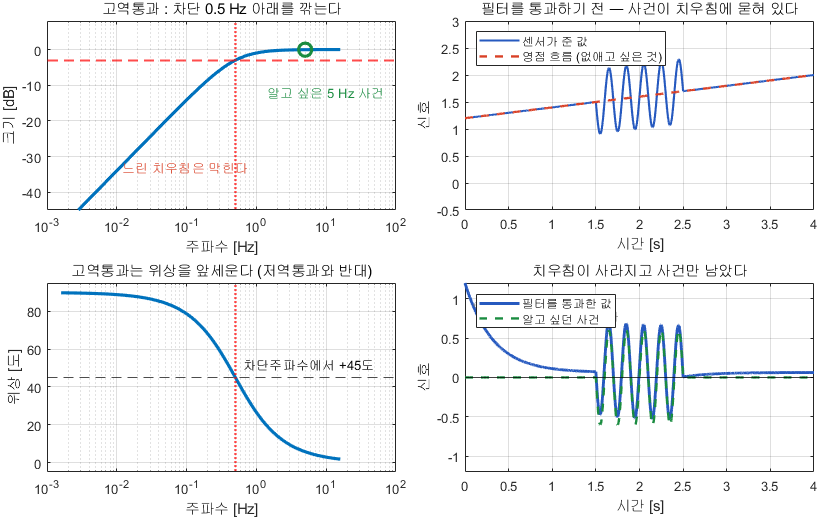

고역통과 : 느린 치우침을 걷어내고 빠른 사건만 남긴다

**그림 파일** `w08_hpf.png` — `make_figures.m` 의 `fig_hpf` · 다시 만들려면 `make_figures('w08_hpf')`

**만드는 곳** — `make_figures.m` 의 `fig_hpf` **직접 바꿔 보려면** — 함수 안의 차단주파수 $0.5$ Hz 를 $2$ 로 올리면 사건까지 함께 깎여 나갑니다

그림 해석 — **저역통과 그림과 좌우가 반대라는 점을 보십시오**

실무 용도가 분명합니다 — **가속도계나 자이로의 드리프트 제거**, 진동 신호에서 사건 검출, 심전도의 기저선 제거 등입니다. 저역통과가 "잡음 제거" 라면 고역통과는 "치우침 제거" 입니다.

읽을 것

- 원래 신호에는 서서히 올라가는 치우침이 있어 **사건이 묻혀 있다**

- 고역통과를 지나면 치우침이 사라지고 사건만 남는다

- 위상이 $+$ 쪽이다. 저역통과가 늦추는 것과 반대로 **앞세운다**

위상을 앞세운다는 것이 어디서 본 이야기 같다면 맞습니다. **미분기가 하는 일이 이것이고, 7주차의 PD 와 10주차의 Lead 가 같은 계열입니다.**


$$\frac{s}{s+\omega_0} \quad\text{와}\quad \frac{K_d\,s}{s/N + 1} \quad\text{는 같은 모양이다}$$


## 7-8. 네 가지 필터를 한눈에

저역통과·고역통과에 두 가지를 더하면 기본형이 넷입니다.

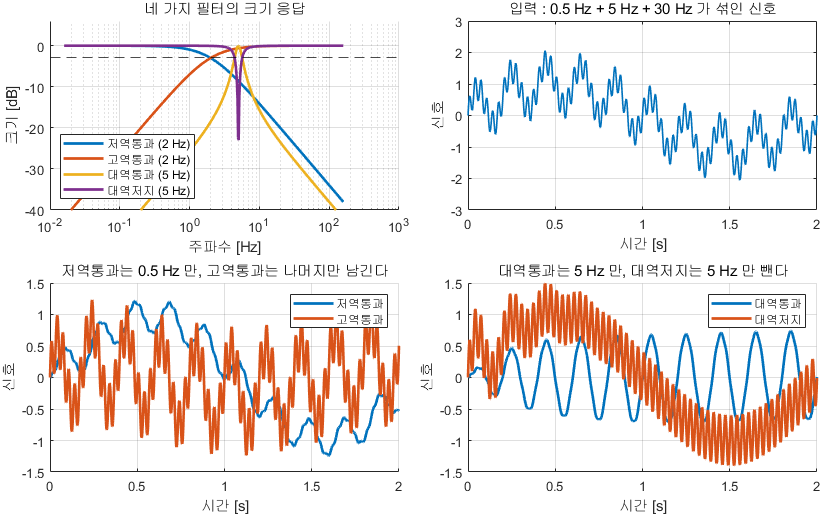

같은 신호를 네 필터에 통과시켜 본 것

**그림 파일** `w08_filters.png` — `make_figures.m` 의 `fig_filter_family` · 다시 만들려면 `make_figures('w08_filters')`

**만드는 곳** — `make_figures.m` 의 `fig_filter_family` **직접 바꿔 보려면** — 함수 안의 입력 성분 $0.5$, $5$, $30$ Hz 를 바꾸면 네 칸이 함께 달라집니다

그림 해석

필터는 **더하기와 빼기**로 만들어집니다. 대역통과 $=$ 저역통과 $\times$ 고역통과, 대역저지 $=$ 전체 $-$ 대역통과입니다.

입력은 $0.5$ Hz + $5$ Hz + $30$ Hz 세 성분이 섞인 신호입니다. 각 필터가 그중 무엇을 남기는지 시간축에서 바로 보입니다.

## 7-9. 이 과목의 플랜트도 사실 필터다

여기까지 오면 뒤집어 볼 수 있습니다. **우리가 제어하려는 대상 자체가 이미 저역통과 필터입니다.**

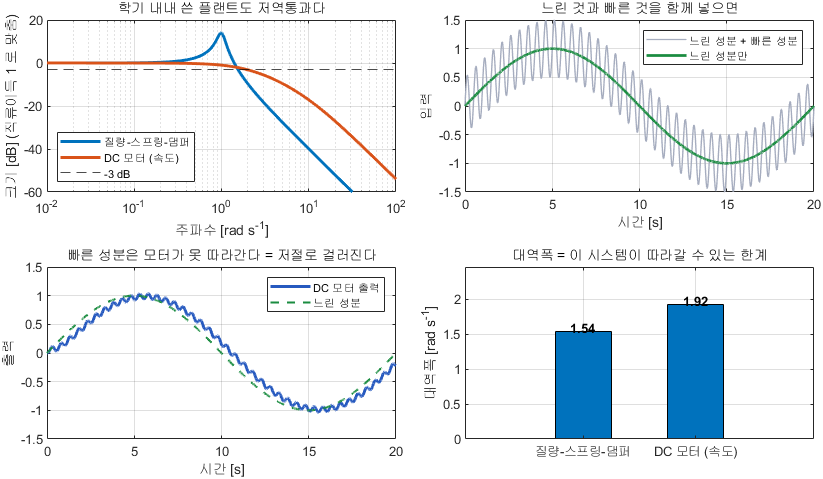

학기 내내 쓴 플랜트도 저역통과다

**그림 파일** `w08_plant_lpf.png` — `make_figures.m` 의 `fig_plant_is_lpf` · 다시 만들려면 `make_figures('w08_plant_lpf')`

**만드는 곳** — `make_figures.m` 의 `fig_plant_is_lpf` **직접 확인해 보려면** — 명령창에 `bandwidth(plant_msd())` 와 `bandwidth(plant_dcmotor('speed'))` 를 쳐 보십시오

그림 해석

**아무도 필터를 넣지 않았는데 필터처럼 동작합니다.** 물리적인 관성과 마찰 자체가 저역통과 필터이기 때문입니다. 그래서 대역폭은 "이 시스템이 따라갈 수 있는 한계" 라고 읽으면 됩니다.

물리적으로 당연합니다.

- 질량은 관성이 있어 빨리 흔들리지 않는다

- 코일은 인덕턴스가 있어 전류가 급히 바뀌지 않는다

- 열은 천천히 퍼진다

그래서 **빠른 지령은 아무리 넣어도 따라오지 못하고**, 그 한계를 숫자로 적은 것이 대역폭입니다.

다만 주의할 것이 하나 있습니다. 질량-스프링-댐퍼의 크기 곡선에는 **봉우리**가 있습니다 (감쇠비가 $0.1$ 이라서). 저역통과이긴 하지만 **차단주파수 근처를 오히려 키웁니다.** 6절에서 본 공진입니다. 필터로 쓸 생각이라면 감쇠비를 $0.707$ 이상으로 잡아야 합니다.

Gm = plant_msd();
Gd = plant_dcmotor('speed');
plant   = ["질량-스프링-댐퍼"; "DC 모터 (속도)"];
bw_rad  = [bandwidth(Gm); bandwidth(Gd)];     % 대역폭 [rad/s]
bw_Hz   = bw_rad/(2*pi);                      % 대역폭 [Hz]
table(plant, bw_rad, bw_Hz)

읽는 법

- 대역폭보다 훨씬 빠른 지령은 아무리 넣어도 **못 따라옵니다**

- 반대로 대역폭 안쪽의 잡음은 그대로 출력에 나옵니다

- 그래서 대역폭을 넓히면 빨라지지만 **잡음에 약해집니다**

- 10주차에서 이 맞바꿈을 설계에 그대로 씁니다 (Lead 는 넓히고 Lag 는 좁힌다)

## 7-10. 1차와 2차의 대역폭 — 강의자료 11~12쪽

차수가 올라가면 어떻게 되는지도 강의자료에 있습니다.

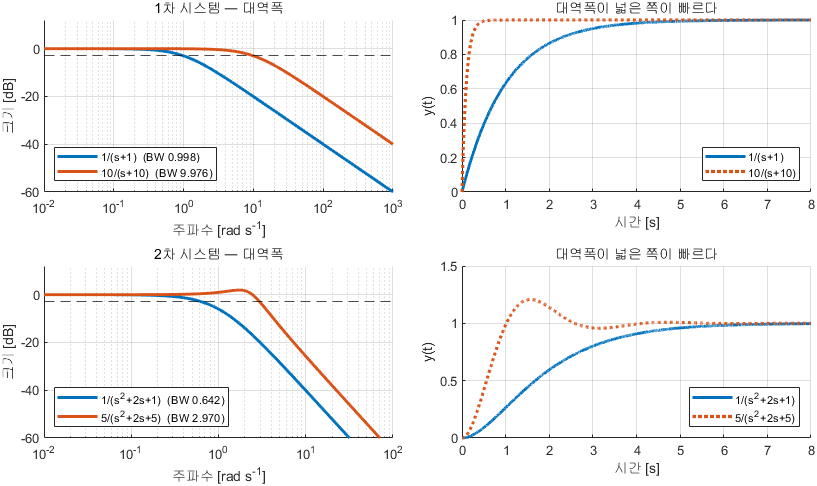

1차·2차 시스템의 대역폭과 계단응답 (강의자료 11~12쪽)

**그림 파일** `w08_bw_order.png` — `make_figures.m` 의 `fig_bw_order` · 다시 만들려면 `make_figures('w08_bw_order')`

**만드는 곳** — `make_figures.m` 의 `fig_bw_order` **직접 확인해 보려면** — 명령창에 `bandwidth(tf(10,[1 10]))` 처럼 직접 계산해 보십시오

그림 해석 — **왼쪽에서 대역폭을 읽고, 오른쪽에서 빠르기를 확인합니다**

외울 한 줄 — **대역폭이 넓으면 빠릅니다.** 어림으로는 $t_r \approx 2/\omega_{BW}$ 정도로 봅니다. 9주차에서 이 대응을 더 다룹니다.

강의자료의 숫자와 대조해 보면

system_name = ["1/(s+1)"; "10/(s+10)"; "1/(s^2+2s+1)"; "5/(s^2+2s+5)"];
bw_calc = [bandwidth(tf(1,[1 1]))
           bandwidth(tf(10,[1 10]))
           bandwidth(tf(1,[1 2 1]))
           bandwidth(tf(5,[1 2 5]))];
bw_slide = [0.9976; 9.9763; 0.6423; 2.9700];   % 강의자료 11~12 쪽의 값
table(system_name, bw_calc, bw_slide)

두 열이 소수점 넷째 자리까지 같습니다. 이 실습이 강의자료와 같은 것을 계산하고 있다는 증거입니다.

읽을 것

- 1차는 차단 뒤 $-20$ dB/dec, 2차는 $-40$ dB/dec 로 더 가파르게 떨어집니다

- 즉 **차수가 높을수록 잘 막습니다.** 대신 위상이 더 많이 깎입니다

- 막는 능력과 위상 지연은 언제나 함께 갑니다. 공짜가 없습니다

## 8. Simulink 로 직접 재 보기

오늘의 마지막은 **실험**입니다. 전달함수를 모른다고 치고, 사인을 넣어 보드 선도를 만들어 봅니다.

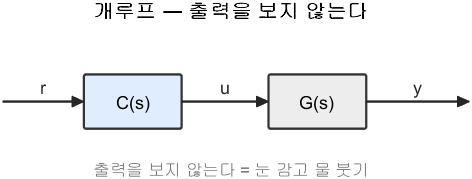

측정 대상은 열린 시스템이다

**그림 파일** `loop_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_open')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('open', ...)` 로 부릅니다 **직접 해 보려면** — `W08_03_run_simulink.m` 을 실행하면 `W08_SineSweep.slx` 로 이 측정을 자동으로 반복합니다

그림 해석

이 그림이 단순한 것이 핵심입니다. **모델이 없어도 잴 수 있다**는 주파수응답의 장점이 여기서 나옵니다. 실물 장비에 사인을 넣고 출력을 오실로스코프로 보면 그대로 보드 선도가 됩니다.

절차는 이렇습니다.

- 주파수를 하나 정해 사인을 넣는다

- 과도응답이 사라질 때까지 **충분히 기다린다**

- 마지막 몇 주기만 잘라 진폭비와 위상차를 계산한다

- 주파수를 바꿔 반복한다

모델을 열기 전에, 오늘 처음 보는 블록 하나를 먼저 봅니다.

`Sine Wave` — 사인파를 만드는 블록

- 하는 일 — $u(t) = A\sin(\omega t + \phi) + b$ 를 매 시각 계산해 내보낸다

- `Amplitude` — 진폭 $A$. 오늘은 $1$ 로 둔다. 선형 시스템이므로 진폭은 결과에 영향을 주지 않는다 (비율만 보기 때문)

- `Frequency` — 각주파수 $\omega$. 단위가 **Hz 가 아니라 rad/s** 다. 보드 선도의 가로축과 같은 단위이므로 그대로 넣으면 된다

- `Phase` — 시작 위상 $\phi$. 오늘은 $0$ 으로 둔다

- `Bias` — 더해지는 상수 $b$. 오늘은 $0$

- `Sample time` — $0$ 으로 두면 연속시간 신호가 된다

오늘 바꾸는 것은 `Frequency` **하나뿐입니다.** 스크립트가 이 값을 `logspace` 로 만든 목록에서 하나씩 꺼내 넣고, 그때마다 `sim` 을 부릅니다. 사람이 손으로 주파수 손잡이를 돌려 가며 재는 것과 정확히 같은 일입니다.

실습 스크립트에서 확인할 것

- `W08_01_sine_to_bode.m` — 손으로 재는 두 가지 방법과 이론값 대조

- `W08_02_bode_asymptotes.m` — 점근선 손작도

- `W08_03_run_simulink.m` — `W08_SineSweep.slx` 로 주파수를 훑어 측정

- `W08_05_rc_simulink.m` — `W08_RC_SineCompare.slx` 로 강의자료 $3$쪽의 두 주파수만 재서 손계산과 대조 ($2$-$4$절)

두 모델의 차이는 목적입니다. `W08_SineSweep.slx` 는 주파수를 **훑어** 보드 선도 전체를 만들고, `W08_RC_SineCompare.slx` 는 주파수 **두 개만** 나란히 놓고 "같은 회로인데 답이 다르다" 를 보여 줍니다.

특히 `W08_03_run_simulink.m` 에서 **짧게 돌리면 얼마나 틀리는지**를 꼭 보십시오. 감쇠비 $0.1$ 인 이 플랜트는 $8$ 초만 돌리면 $71\%$ 나 틀립니다.

## 8-1. 주파수응답을 숫자로 꺼내는 네 가지 명령

`bode` 는 그림을 그려 주지만, 설계에서는 **숫자**가 필요합니다. 한 주파수의 크기와 위상을 꺼내는 방법이 네 가지 있습니다.

**주의 두 가지**

- `bode` 의 크기 출력은 dB 가 아니라 **배수**입니다. dB 로 보려면 `mag2db` 를 씁니다

- 출력이 `1x1xN` 배열이라 그대로 `plot` 하면 오류가 납니다. `squeeze(m)` 로 폅니다

s = tf('s');
Gb = 4/(s^2 + 0.8*s + 4);
wq = [0.5 1 2 5];
[mg, ph] = bode(Gb, wq);
w      = wq(:);
mag    = squeeze(mg);        % 배수
mag_dB = mag2db(mag);        % 데시벨
phase  = squeeze(ph);        % 도
table(w, mag, mag_dB, phase)

같은 값을 복소수로 직접 얻을 수도 있습니다.

Gjw = evalfr(Gb, 2i)          % w = 2 에서의 G(jw)

mag_check   = abs(Gjw)                % 위 표의 w = 2 줄과 같다
phase_check = rad2deg(angle(Gjw))

bw = bandwidth(Gb)            % 이득이 -3 dB 로 떨어지는 주파수

## 9. 오늘의 정리

- 사인을 넣으면 **같은 주파수의 사인**이 나온다. 크기와 위상만 달라진다

- 그 크기비와 위상차가 곧 $G(j\omega)$ 다. $s$ 자리에 $j\omega$ 를 넣으면 끝이다

- 입력 진폭 $A$ 는 출력에서 $A|G|$ 가 된다. **비를 재므로 보드 선도에 **$A$** 는 없다**

- $f = 1/T = \omega/2\pi$. Simulink `Sine Wave` 의 `Frequency` 는 **rad/s** 이므로 $f$ Hz 를 넣으려면 `2*pi*f` 라고 적어야 한다

- **보드 선도**는 가로축을 로그로, 세로축을 $20\log_{10}|G|$ 로 바꿔 그린 것이다. 위상 선도는 세로축을 바꾸지 않는다 (도 단위 그대로)

- 크기는 dB, 주파수는 로그로 그린다. **곱셈이 덧셈이 되기 때문**이다

- **이득 **$K$** 를 키우면 크기 선도는 **$20\log_{10}K$** 만큼 통째로 올라가고 모양은 그대로다. 위상 선도는 꼼짝도 하지 않는다** ($K>0$)

- 그래서 $K$ 를 키우면 $\omega_c$ 와 $\omega_{BW}$ 가 커지고 **응답이 빨라진다** ($t_r \approx 1.8/\omega_{BW}$). 대신 위상이 그대로이므로 위상여유가 줄어 **오버슈트가 커진다**

- 전달함수는 **상수 · 적분기 · 1차 · 2차** 네 조각의 곱이고, 조각마다 점근선을 그려 더하면 전체가 된다

- 시정수 꼴 $(Ts+1)$ 로 정리하고 시작해야 한다. 상수를 빠뜨리지 말 것

- 2차 항은 $\zeta < 0.707$ 이면 봉우리가 생긴다. 대략 $1/(2\zeta)$

- 실험으로 잴 때는 **과도응답이 사라진 뒤에** 재야 한다

## 10. 다음 주 예고

오늘은 "어떻게 생겼는가" 를 봤습니다. 다음 주에는 그 그림으로 **안정도를 판단**합니다.

핵심 질문은 이것 하나입니다.

**개루프의 크기가 **$1$** 이고 위상이 **$-180^\circ$** 이면 폐루프가 불안정해진다. 그 점에서 얼마나 떨어져 있는가?**

그 거리를 **이득여유**와 **위상여유**라고 부릅니다.